# Modelación, Simulación y Análisis de un Balancín Eólico

Amelia Hoyos Vélez y Esteban Álvarez Zuluaga

## 1. Introducción 

### 1.1 Planteamiento del problema

El aerobalancín, balancín eólico o aeropéndulo doble es un dispositivo empleado en laboratorios de control para la validación experimental de estrategias de control que posteriormente se aplican en sistemas de la industria aeroespacial y mecatrónica, como por ejemplo en vehículos autónomos no tripulados [1]. Este modelo permite estudiar una plataforma considerablemente más simple que las utilizadas en aplicaciones industriales reales, ya que posee un único grado de libertad. No obstante, conserva una estructura MISO (Multiple Input Single Output) que proporciona una dinámica suficientemente rica para el análisis y diseño de estrategias de control. Por esta razón, el estudio de este sistema constituye un ejercicio cuyos resultados pueden extrapolarse a problemas del mundo real.

En el caso del aerobalancín, el problema se formula como el modelado matemático de un péndulo cuyo pivote no se encuentra en uno de sus extremos, sino en una posición intermedia de la barra, lo que implica que uno de sus lados pueda ser más largo que el otro. En ambos extremos de la barra se disponen hélices propulsoras, controladas de manera independiente, que generan dos pares de control aplicados al sistema.

El objetivo principal es obtener una descripción analítica de la dinámica no lineal del sistema y llevar a cabo simulaciones numéricas que permitan analizar su comportamiento. A partir de este análisis, se pretende diseñar estrategias de control óptimo orientadas, por ejemplo, a la estabilización del sistema en torno a un punto de equilibrio arbitrario.

### 1.2 Modelo matemático

El modelo se deriva de sistemas similares, como el aeropéndulo con una sola hélice propulsora [2], [3]. El sistema del aerobalancín consiste en una barra rígida sujeta a un pivote en cuyos extremos están acoplados dos motores con hélices. Cada hélice genera una fuerza de empuje perpendicular a la barra, la cual induce un momento de fuerza que hace girar el sistema alrededor de su pivote, ubiccado en el origen del sistema de referencia. 

Supongamos que la fuerza de empuje $T_1$ que produce el primer motor a una distancia $l_1$ del pivote genera un momento positivo $\vec{M}_1 = l_1 \times T_1$ y que $T_2$ producida por el segundo motor a una distancia $l_2$ del pivote genera un momento negativo $\vec{M}_2 = l_2 \times T_2$. El centro de gravedad del sistema puede no coincidir con el pivote, por lo que el peso del aeropéndulo también produce un momento de fuerza. Dicho momento viene dado por $\vec{M_3} = mgd\sin(\phi)  $, donde $g$ es la aceleración debida a la gravedad, $m$ es la masa del péndulo, $d$ es la distancia desde el pivote hasta el centro de gravedad, y $\phi$ es el ángulo positivo medido entre el eje$y$ negativo y el eje$1$del péndulo. La masa del sistema es $m = m_b + m_1+m_2$, donde $m_b$ es la masa de la barra, $m_1$es la masa del primer motor y $m_2$ la masa del segundo motor.

Por último, la fuerza de arrastre del aire, que se opone al movimiento, se modela mediante un término lineal de rozamiento viscoso $\vec{M_4} = -c\dot{\theta}$ donde $c$ es el coeficiente de amortiguamiento viscoso del aire, $\theta = \frac{\pi}{2} - \phi$ es el ángulo medido respecto a la horizontal positiva y $\dot{\theta}$ es su velocidad angular.

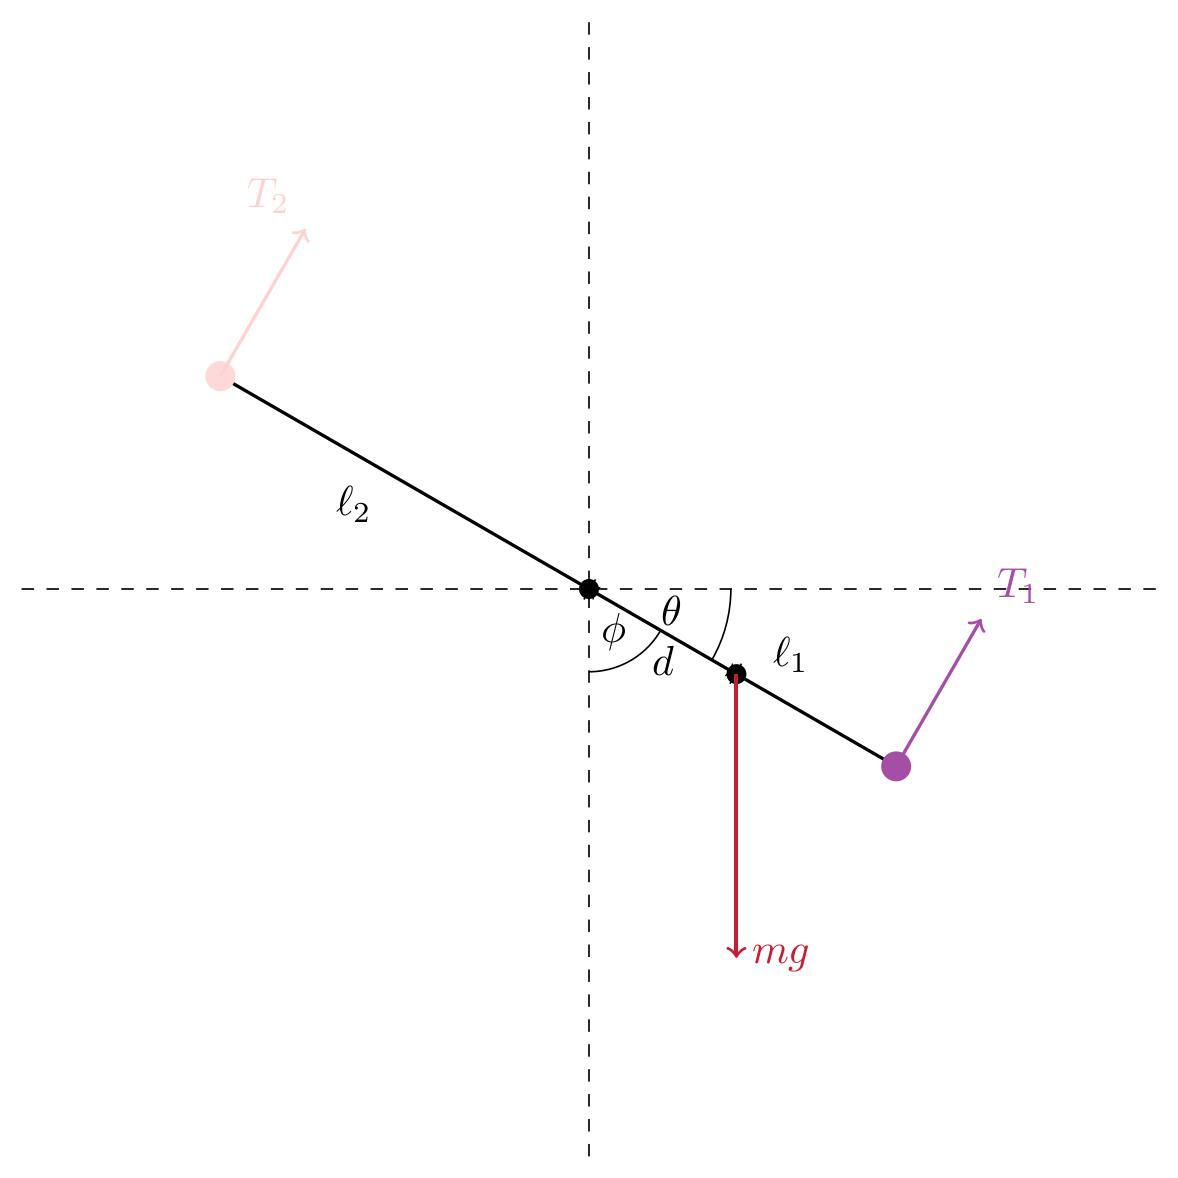

**Figura 1. Diagrama de cuerpo libre de un aerobalancín**

Según la formulación de Newton–Euler que describe la dinámica de sólidos rígidos, suponiendo un movimiento rotacional alrededor de un eje fijo de un cuerpo rígido con un momento de inercia constante y momentos respecto a dicho eje [4], la dinámica del sistema puede expresarse mediante

$\matrix{J\ddot{\theta} = \sum_{i=1}^4 M_i && (1)}$,

donde $J$ es el momento de inercia rotacional del sistema. La ecuación dinámica del sistema es,

$\matrix{ J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\sin(\phi) - c\dot{\theta} && (2)}$.

La ecuación, debido a que $\theta = \frac{\pi}{2} - \phi$, se reescribe como

$\matrix{J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\cos\left( \theta\right) - c\dot{\theta} && (3)}
$.

En base al modelo teórico, se construye el sistema de variables de estado. Se asigna,


$$\matrix{x_1 = \theta, \qquad x_2 = \dot{\theta}, \qquad u_1 = T_1, \qquad u_2 = T_2. && (4)}


$$


Así que,


$$\matrix{\mathbf{x} = \left[\begin{array}{c} x_1 \\ x_2 \end{array}\right], \qquad \mathbf{u} = \left[\begin{array}{c} u_1 \\ u_2 \end{array}\right]. && (5)}
$$


El sistema de variables de estado es,


$$\matrix{\left\{\begin{array}{l} \dot{x}_1 = x_2, \\ \dot{x}_2 = \frac{1}{J}\left(u_1 l_1 - u_2 l_2 - mgd\cos x_1 - cx_2\right). \end{array}\right. && (6)}
$$


En forma vectorial,


$$\matrix{\dot{\mathbf{x}} = \left[\begin{array}{c} x_2 \\ \frac{1}{J}\left(u_1 l_1 - u_2 l_2 - mgd\cos x_1 - cx_2\right) \end{array}\right]. && (7)}
$$


Así que $\dot{x} = f(\mathbf{x},\mathbf{u})$. Como puede verse, el modelo es no lineal debido al término $\frac{mgd}{J}\cos x_1$ que es de segundo orden.

### 1.3 Variables y Parámetros del Modelo

Si el punto $d$está sobre $l_1$, se define como positivo, y si está sobre $l_2$ es negativo; $d$ se calculará por defecto como


$$\matrix{d = \frac{l_1 + l_2}{2} - l_2. && (8)}
$$


El momento de inercia del aerobalancín respecto al pivote se obtiene considerando la contribución de cada uno de los elementos del sistema: la barra y los motores ubicados en sus extremos. Para trasladar los momentos de inercia al eje de rotación del sistema se emplea el teorema de ejes paralelos.

$\matrix{J = J_{\text{barra}} + J_{\text{motor}_1} + J_{\text{motor}_2} = 
\left(\frac{1}{12} m_b L^2 + m_b d^2 \right)
+ m_1 l_1^2
+ m_2 l_2^2 && (9)}
$.

El modelo del balancín eólico se formula a partir de los parámetros, vaiables de estado y entradas del sistema, los cuales se presentan en las Tablas 1, 2 y 3, respectivamente.

**Tabla 1: Parámetros del modelo**

**Tabla 2: Variables de estado del modelo**

**Tabla 3: Entradas del modelo**

### 1.4 Supuestos

Se establecen los siguientes supuestos con respecto a la modelación del sistema:

- Los parámetros son constantes, no dependen del tiempo.

- Movimiento en un solo plano.

- El campo de aire es constante, no hay turbulencia.

- El amortiguamiento debido a la fricción viscosa es lineal.

### 1.5 Hipótesis

Se plantean las siguientes hipótesis

- Si $l_2 = 0$ y $T_1 = T_2 = 0 \text{ N}$, entonces el aeropéndulo doble tiene el mismo comportamiento que el de un péndulo ideal.

- Con entrada constante, si $c = 0$, entonces el aeropéndulo oscila indefinidamente.

- Con entrada constante, para $c = 0$, entre mayor distancia del pivote al centro de masa, mayor será el periodo de oscilación. 

- Con entrada constante, para $c \neq 0$, entonces el aeropéndulo se amortigua hasta un punto de equilibrio.

- Con entrada constante, a mayor masa, mayor $|\theta_{eq}|$.

- Con entrada constante, con un alto coeficiente de fricción se espera que el sistema se estabilize más rápido.

- Con una entrada unilateral, se espera que el sistema comienze a dar vueltas sin estabilizarse.

- Con una entrada sinusoidal, aún si $c \neq 0$, el sistema oscila.

- Con una entrada delta, el sistema se tarda más tiempo en estabilizarse.

## 2. Métodos

*Implementación del modelo de simulación: *Se definen los parámetros, la función de entrada y las condiciones iniciales por defecto. Se implementa el modelo de simulación y se resuelve obteniendo las variables de estado mediante el método de Runge–Kutta. También se definen funciones auxiliares para la generación de gráficas.

*Comparación con el caso límite: *Se compara el aeropéndulo para probar la Hipótesis 1 con el caso del péndulo ideal. Su comportamiento se contrasta cualitativamente con el esperado para el péndulo ideal y, para $$\phi = 10^\circ$$, se verifica que el período simulado coincida con $$T = 2\pi\sqrt{\frac{L}{g}}$$, que corresponde al período teórico para ángulos pequeños, con un bajo porcentaje de error.

*Análisis del comportamiento con variación de parámetros: *Se realizan varios casos de variación de parámetros.

- Se realizan varias simulaciones variando los parámetros y manteniendo el resto iguales a los valores por defecto. Se varía la ubicación del pivote considerando fricción viscosa nula ($$b = 0$), modificando $l_1$ entre $$3\,\text{cm}$ y $27\,\text{cm}$ y manteniendo $$L = 30\,\text{cm}$$, con el fin de probar las Hipótesis 2 y 3.

- Posteriormente se añade fricción viscosa ($c = 0.1$) para comprobar la Hipótesis 4, variando los parámetros de la misma manera que en el caso anterior.

- Se realiza además un procedimiento para encontrar los puntos de equilibrio con el objetivo de verificar que el modelo esté correctamente implementado.

- Se varía la masa entre $$0.3$$ y $$1.0\,\text{kg}$$ para comprobar la Hipótesis 5, comparando el valor teórico del punto de equilibrio con el obtenido mediante simulación.

- Finalmente, para comprobar la Hipótesis 6, con $$l_1 = 0.21\,\text{m}$$ y $$l_2 = 0.09\,\text{m}$$, se varían los valores del coeficiente de fricción en una escala logarítmica entre $$c = 0.001\,\text{N\cdot m\cdot s/rad}$$ y $$1,\text{N\cdot m\cdot s/rad}$$.

*Análisis del comportamiento con cambio en el tipo de entrada: *Se realiza la simulación con diferentes tipos de entrada, constante, sinusoidal y delta. Se muestra la simulación por medio de una animación del comportamiento del sistema. Esto se hace para probar la Hipótesis 7 y la Hipótesis 8.

## 3. Resultados

### **3.1 Variables por defecto y funciones auxiliares**

clear; clc; close all;

% Parámetros físicos
params.mb = 0.1;       % Masa de la barra (kg)
params.m1 = 0.2;       % Masa del rotor 1 (kg)
params.m2 = 0.2;       % Masa del rotor 2(kg)
params.l1 = 0.4;       % Distancia al rotor 1 (m)
params.l2 = 0.2;       % Distancia al rotor 2 (m)
params.g = 9.81;       % Gravedad (m/s^2)
params.c = 0.1;        % Coeficiente de amortiguamiento (N·m·s/rad)

%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s

x0 = [theta0; theta_dot0];

function params = aeropendulum_compute_params(params)

    % Longitud total de la barra
    params.L = params.l1 + params.l2;
    
    % Distancia del pivote al centro de gravedad
    params.d = (params.l1 + params.l2)/2 - params.l2;
    
    % Masa total
    params.m = params.mb + params.m1 + params.m2;
    
    % Momento de inercia de la barra
    J_bar = (1/12)*params.mb*params.L^2 + params.mb*params.d^2;
    
    % Momento de inercia de los rotores
    J_r1 = params.m1 * params.l1^2;
    J_r2 = params.m2 * params.l2^2;
    
    % Momento de inercia total
    params.J = J_bar + J_r1 + J_r2;

end

params = aeropendulum_compute_params(params);

Se presenta la dinámica del modelo codificada, con una función auxiliar que permite definir la entrada que se aplicará al sistema.

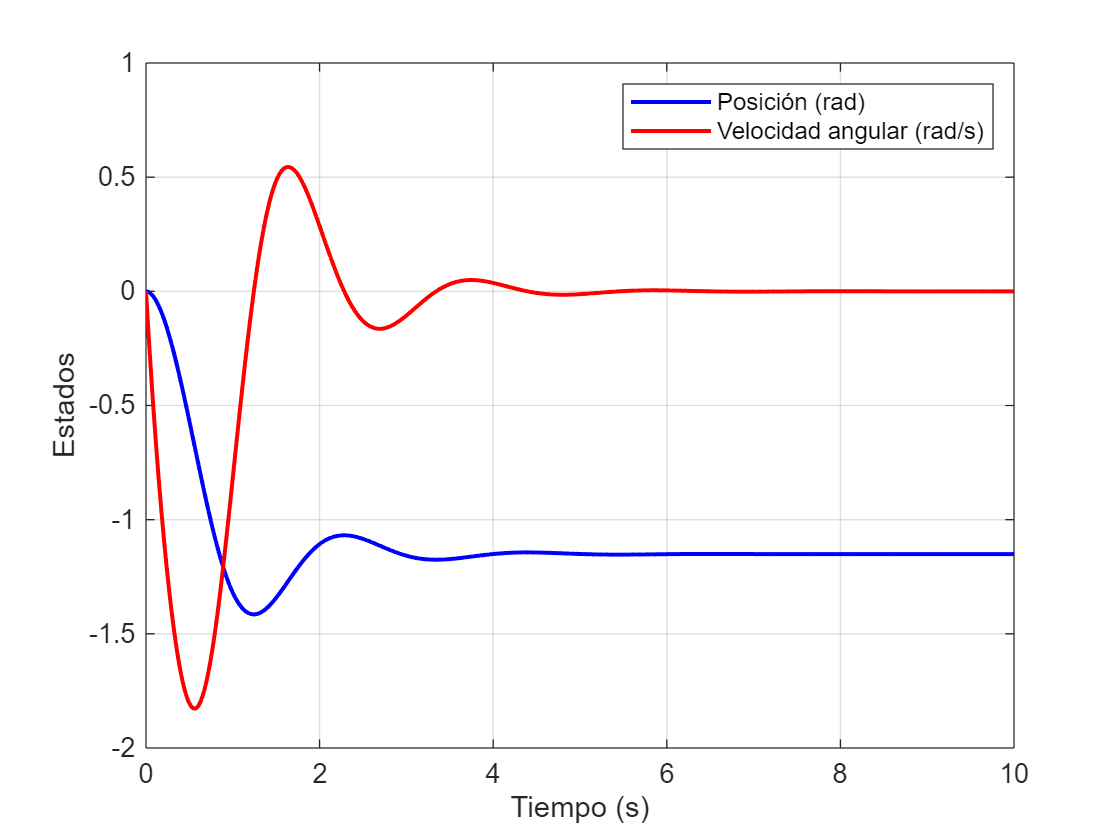

% Ecuación dinámica del aerobalancín
function dx = aeropendulum_dynamics(t,x,params,thrust_fun)
    
    % Entradas:
    %   t           -> tiempo
    %   x           -> vector de estado [theta; theta_dot]
    %   params      -> parámetros físicos del sistema
    %   thrust_fun  -> función de empuje [T1,T2] = thrust_fun(t,theta,theta_dot)

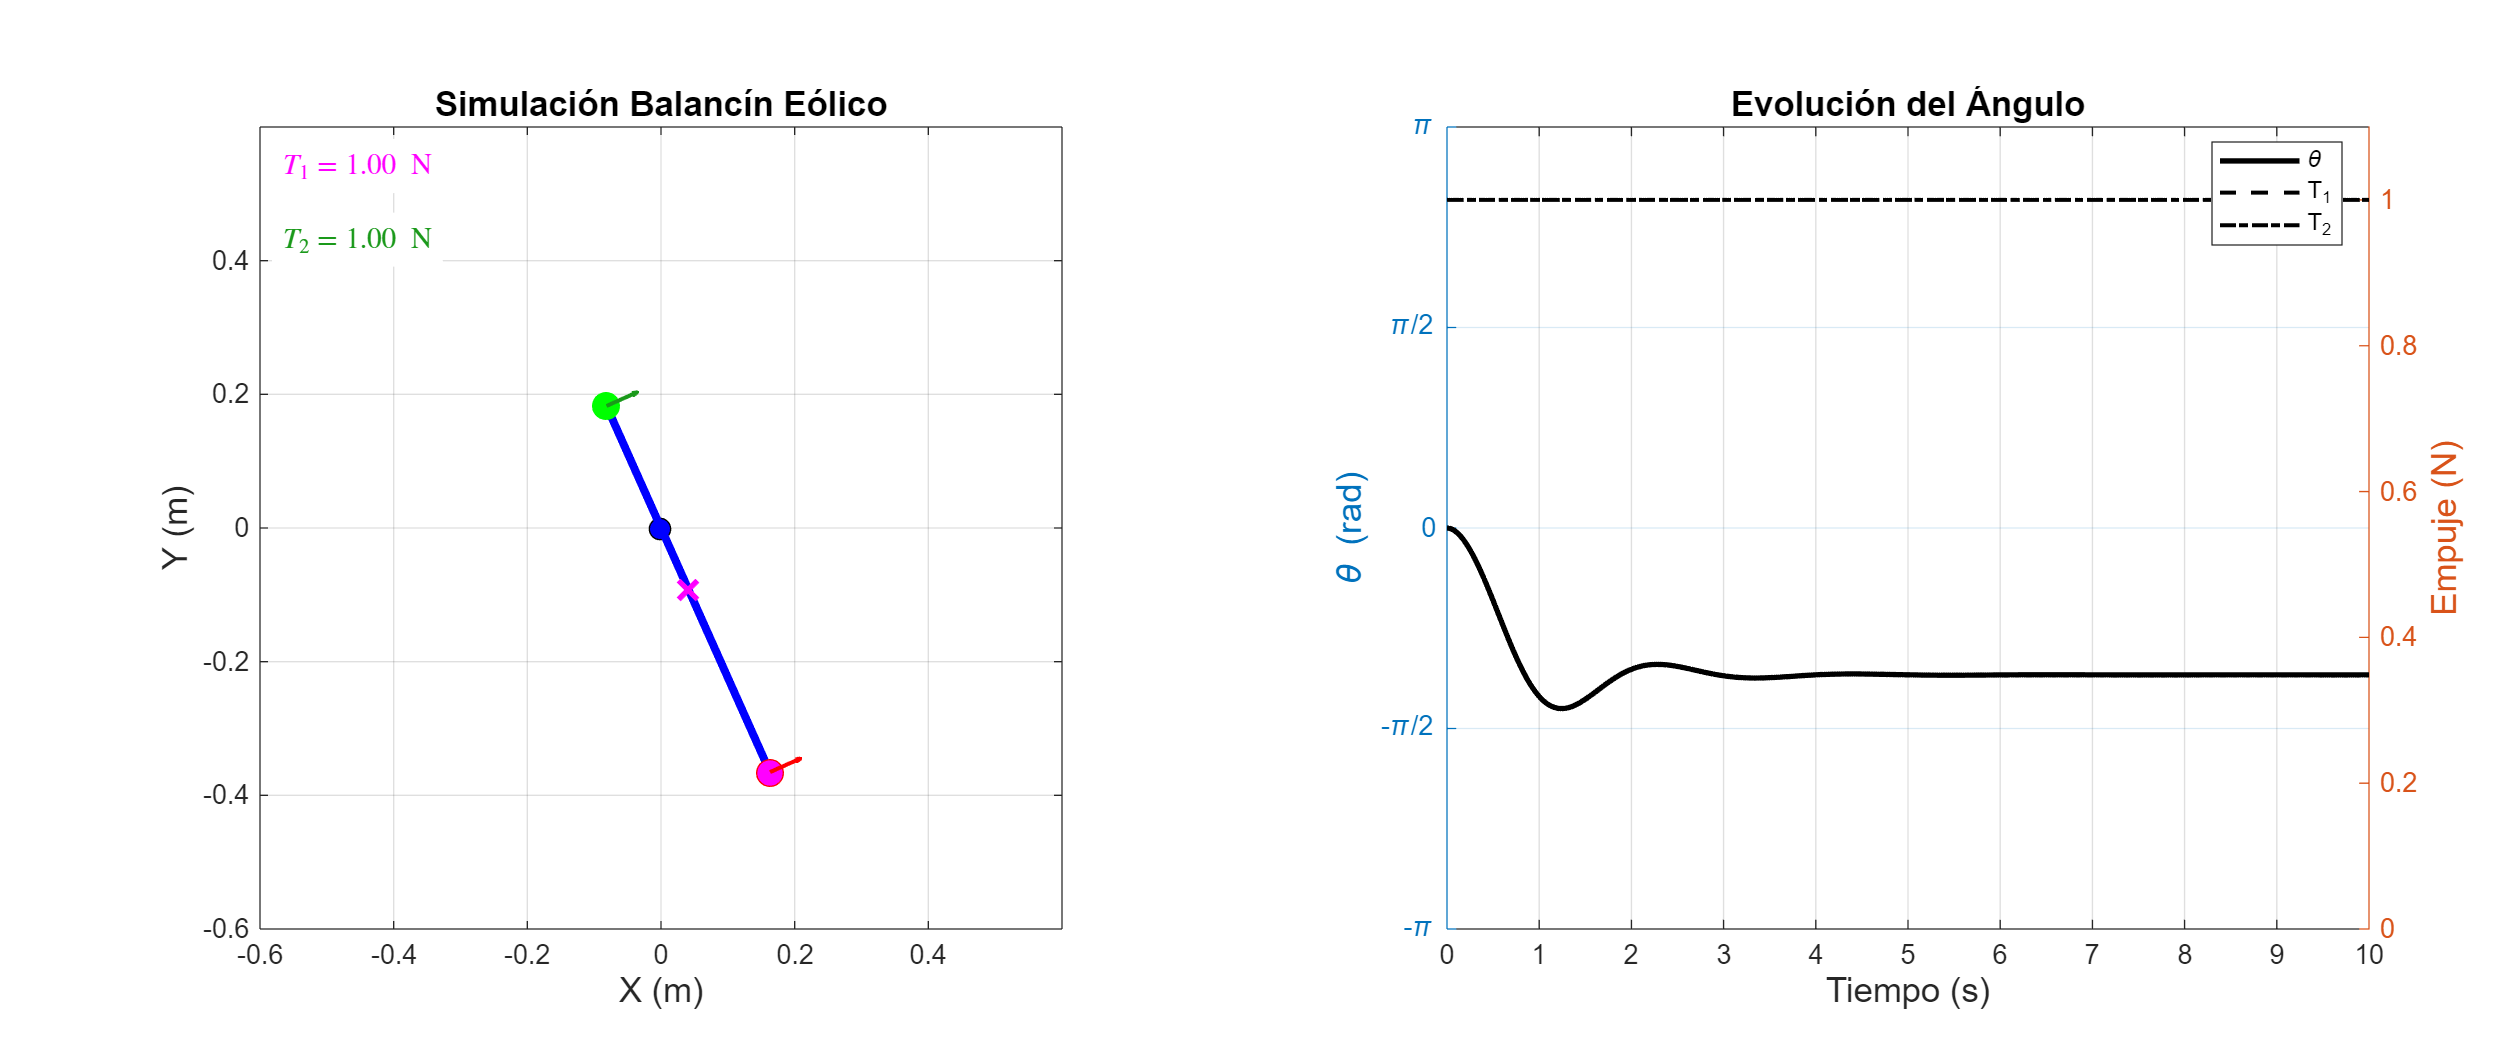

    %
    % Salida:
    %   dx          -> derivada del vector de estado

    
    %% Estados
    theta = x(1);
    theta_dot = x(2);
    
    % Mantener theta en [-pi, pi]
    theta = atan2(sin(theta),cos(theta));
    
    %% Empujes de los rotores
    [T1,T2] = thrust_fun(t,theta,theta_dot);
    
    %% Dinámica del sistema
    theta_ddot = ( ...
          T1*params.l1 ...
        - T2*params.l2 ...
        - params.m*params.g*params.d*sin(pi/2 - theta) ...
        - params.c*theta_dot ...
        ) / params.J;
    
    %% Vector de derivadas
    dx = [theta_dot; theta_ddot];

end
% Modelo de empuje constante para los rotores del aerobalancín.
function [T1,T2] = thrust_constant(~, ~, ~)
% Salidas:
%   T1 -> Empuje generado por el rotor 1 (N)
%   T2 -> Empuje generado por el rotor 2 (N)

    T1 = 1;   % Empuje constante del rotor 1 (N)
    T2 = 1;   % Empuje constante del rotor 2 (N)
end

Se definen algunas funciones auxiliares para resolver el problema. Entre estas se encuentra una función para simular el comportamiento del aeropéndulo mediante el método de Runge–Kutta.

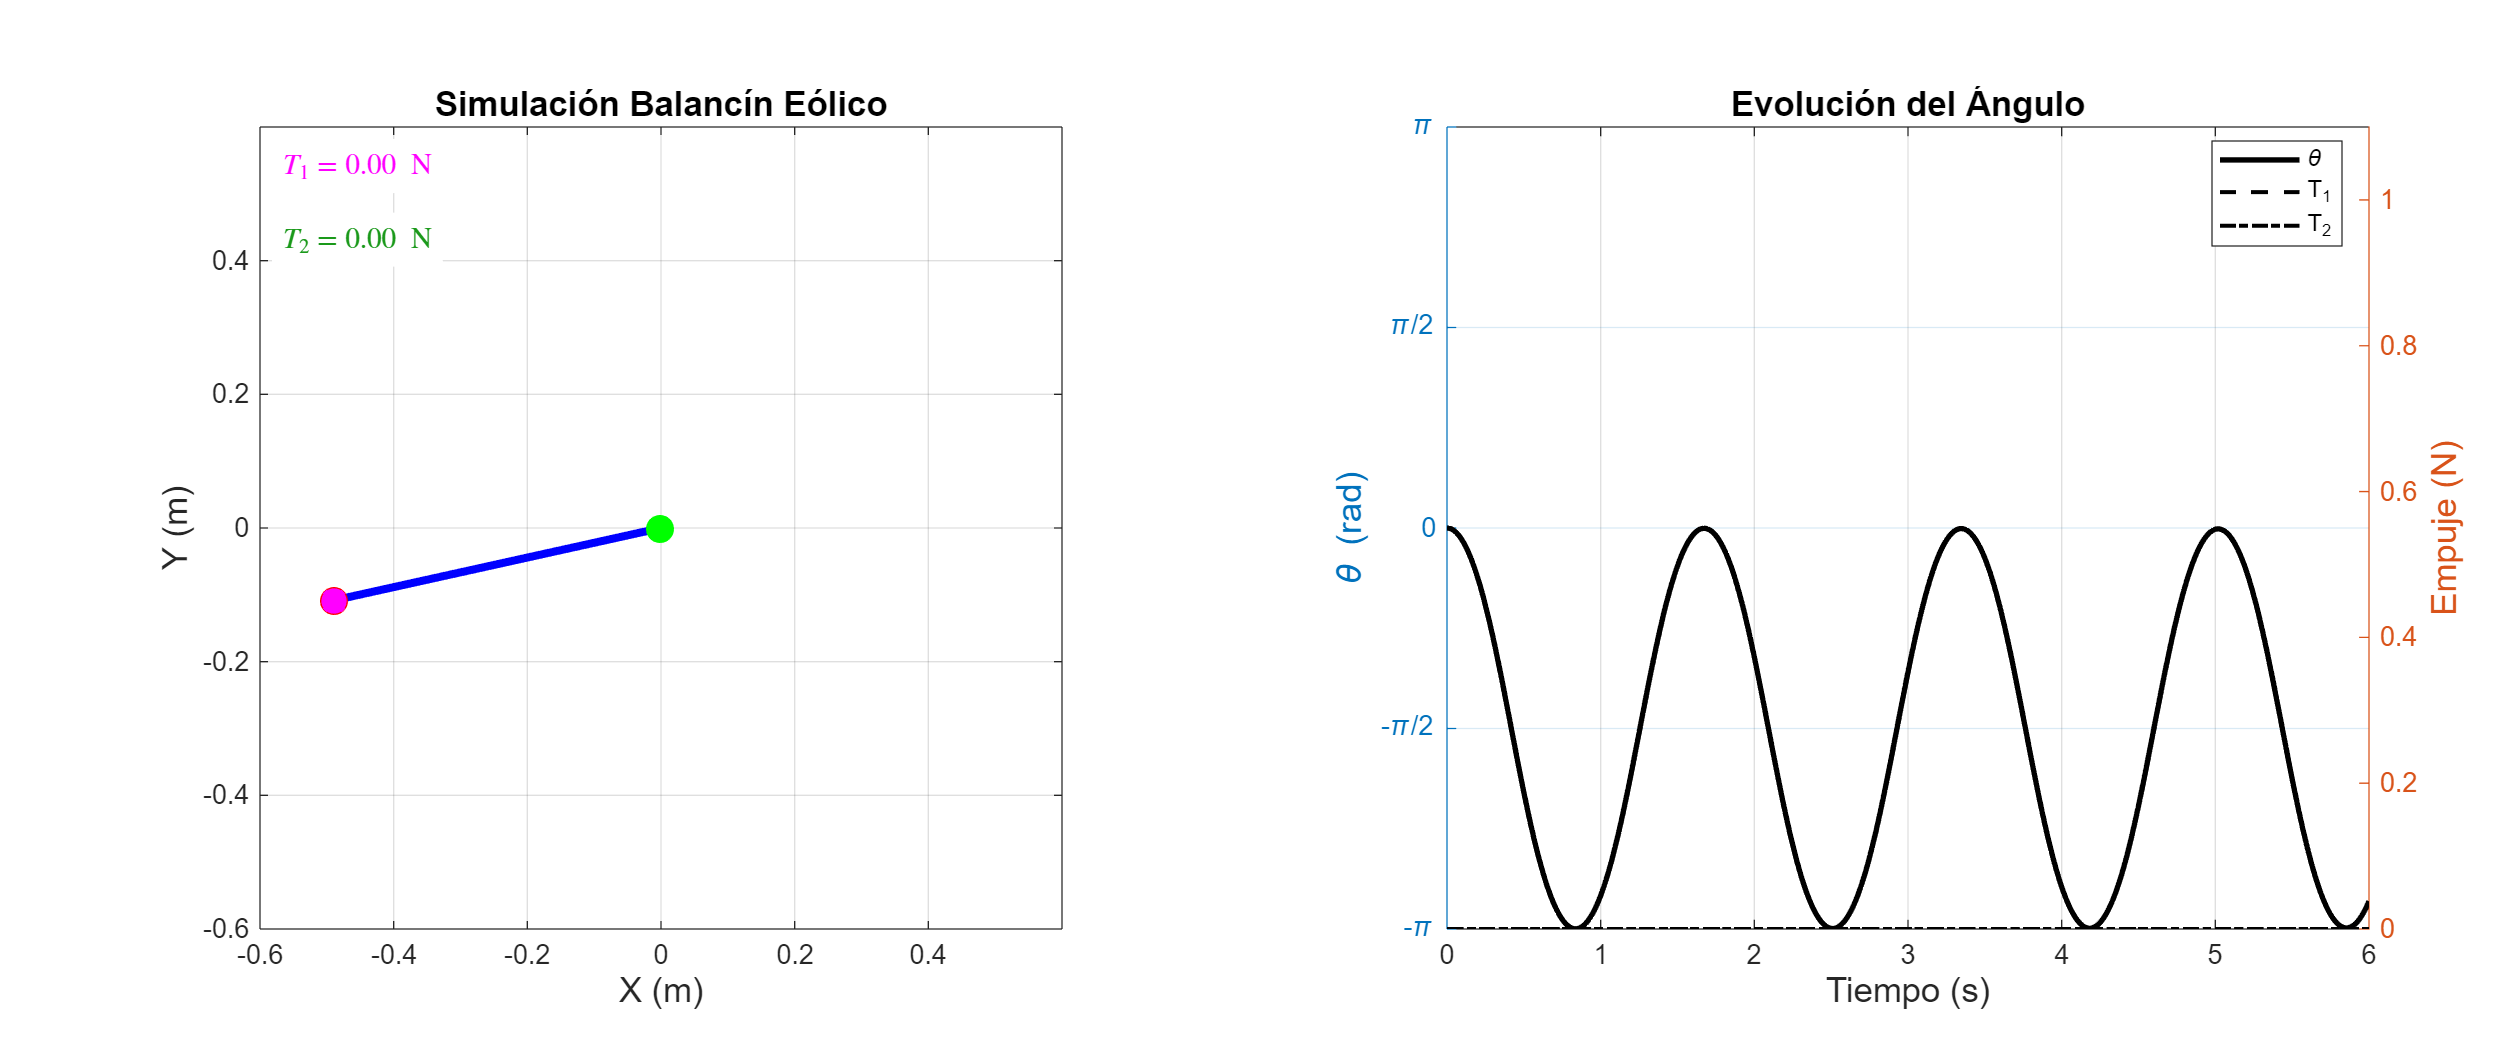

% Simula la dinámica del aerobalancín
function [t,theta,theta_dot,sol] = simulate_aeropendulum(params,x0,tspan,thrust_fun)

    % Entradas:
    %   params      -> parámetros físicos del sistema
    %   x0          -> condiciones iniciales [theta0; theta_dot0]
    %   tspan       -> vector de tiempo de simulación

    %   thrust_fun  -> función de empuje de los rotores
    %
    % Salidas:
    %   t           -> vector de tiempo
    %   theta       -> posición angular en [-pi,pi]
    %   theta_dot   -> velocidad angular (rad/s)
    %   sol         -> solución completa del sistema

    % Resolver el sistema dinámico (Runge-Kutta 4,5)
    [t,sol] = ode45(@(t,x) aeropendulum_dynamics(t,x,params,thrust_fun), tspan, x0);

    % Variables de estado
    theta = mod(sol(:,1) + pi, 2*pi) - pi;   % mantener en [-pi,pi]
    theta_dot = sol(:,2);

end

La siguiente función grafica los estados del aerobalancín en función del tiempo.

function plot_aeropendulum_states(t,theta,theta_dot)
% Entradas:
%   t         -> vector de tiempo (s)
%   theta     -> posición angular (rad)
%   theta_dot -> velocidad angular (rad/s)

    figure
    plot(t,theta,'b','LineWidth',1.5)
    hold on
    plot(t,theta_dot,'r','LineWidth',1.5)
    
    xlabel('Tiempo (s)')
    ylabel('Estados')
    legend('Posición (rad)','Velocidad angular (rad/s)')
    grid on
end

La siguiente función es para animar los resultados de la simulación bajo los parámetros seleccionados.

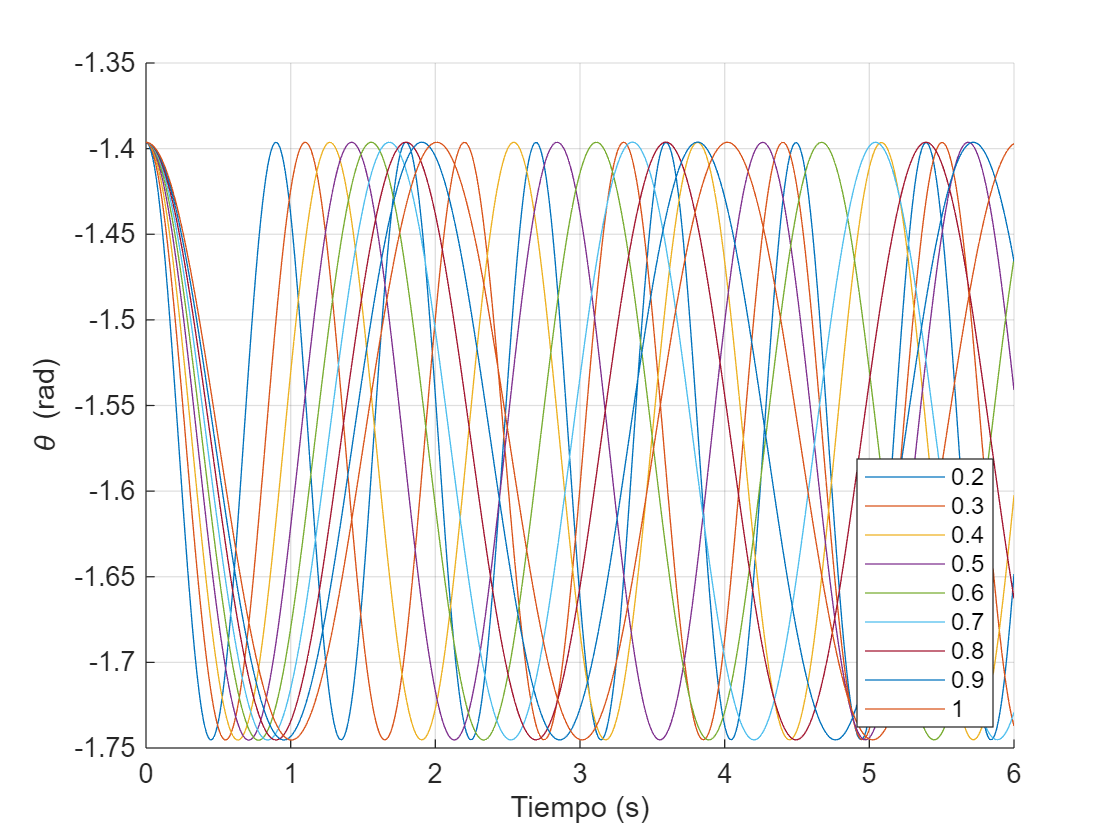

function animate_aeropendulum(t, theta, theta_dot, parameters, thrust_fun, show_thrust)

% Entradas:
% t          -> Vector de tiempo obtenido de la simulación (s)
% theta      -> Vector del ángulo del aeropéndulo en cada instante (rad)
% theta_dot  -> Vector de la velocidad angular (rad/s)
% parameters -> Estructura con parámetros físicos del sistema
% thrust_fun -> Función de empuje de los rotores [T1,T2] = thrust_fun(t,theta,theta_dot)

    l_1 (m)    Periodo simulado (s)    Periodo teórico (s)    Erro rrelativo (%)
    _______    ____________________    ___________________    __________________

      0.2            0.88978                 0.89714                0.82047     
      0.3             1.0942                  1.0988                0.41679     
      0.4             1.2625                  1.2687                0.49048     
      0.5             1.4188                  1.4185               0.023569     
      0.6             1.5631                  1.5539                0.59423     
      0.7             1.6834                  1.6784                0.29617     
      0.8             1.8036                  1.7943                 0.5198     
      0.9             1.8998                  1.9031                0.17457     
        1              2.008                  2.0061 

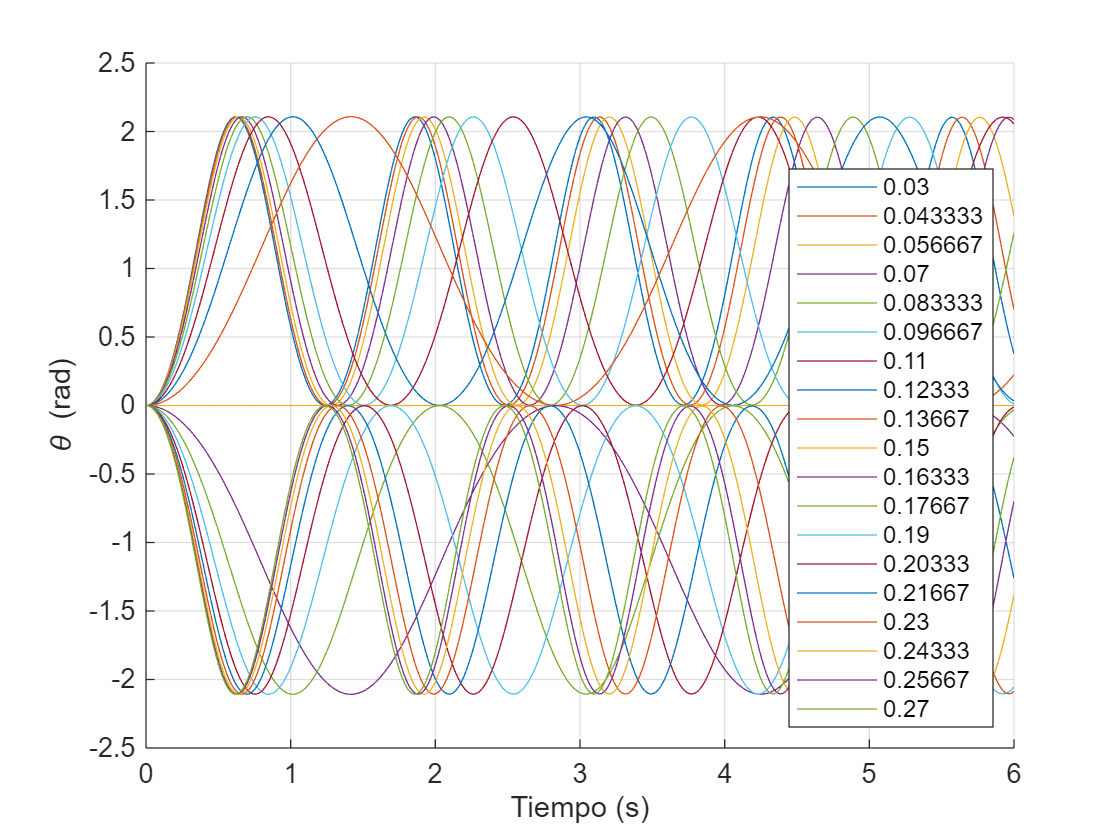

% show_thrust-> true/false para mostrar T1 y T2 en la gráfica de evolución

if nargin < 6
    show_thrust = false;
end

% Extraer parámetros geométricos
l1 = parameters.l1;
l2 = parameters.l2;
d  = parameters.d;

theta = mod(theta + pi, 2*pi) - pi;

%% Crear figura con margen suficiente para etiquetas
fig = figure('Position', [100 100 1300 550]);

%% -------- Animación del Péndulo (ax1) --------
ax1 = subplot(1,2,1);
axis(ax1, 'equal');
axis(ax1, [-0.6 0.6 -0.6 0.6]);
grid(ax1, 'on');
box(ax1, 'on');

xlabel(ax1, 'X (m)', 'Interpreter', 'tex', 'FontSize', 13);
ylabel(ax1, 'Y (m)', 'Interpreter', 'tex', 'FontSize', 13);
title(ax1, 'Simulación Balancín Eólico', ...
    'Interpreter', 'tex', 'FontSize', 13, 'FontWeight', 'bold');

hold(ax1, 'on');

pivot = plot(ax1, 0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
bar   = plot(ax1, [0 0], [0 0], 'b-', 'LineWidth', 3);
r1    = plot(ax1, 0, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'm');
r2    = plot(ax1, 0, 0, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
cg    = plot(ax1, 0, 0, 'mx', 'MarkerSize', 10, 'LineWidth', 2);

label_T1 = text(ax1, -0.57, 0.57, '$T_1 = 0.00\ \mathrm{N}$', ...
    'Interpreter', 'latex', 'FontSize', 11, ...
    'HorizontalAlignment', 'left', ...
    'VerticalAlignment', 'top', ...
    'Color', 'm', ...
    'BackgroundColor', 'white', 'EdgeColor', 'none');

label_T2 = text(ax1, -0.57, 0.46, '$T_2 = 0.00\ \mathrm{N}$', ...
    'Interpreter', 'latex', 'FontSize', 11, ...
    'HorizontalAlignment', 'left', ...
    'VerticalAlignment', 'top', ...
    'Color', [0.1 0.6 0.1], ...
    'BackgroundColor', 'white', 'EdgeColor', 'none');

%% -------- Angulo/Empuje Gráfica (ax2) --------
ax2 = subplot(1,2,2);
grid(ax2, 'on');
box(ax2, 'on');
hold(ax2, 'on');

xlabel(ax2, 'Tiempo (s)', 'Interpreter', 'tex', 'FontSize', 13);
title(ax2, 'Evolución del Ángulo', ...
    'Interpreter', 'tex', 'FontSize', 13, 'FontWeight', 'bold');

% Eje izquierdo: theta
yyaxis(ax2, 'left')
ylabel(ax2, '\theta (rad)', 'Interpreter', 'tex', 'FontSize', 13);

angle_line = animatedline(ax2, 'LineWidth', 2);

ylim(ax2, [-pi pi]);
set(ax2, 'YTick', [-pi -pi/2 0 pi/2 pi])

set(ax2, 'YTickLabel', {'-\pi','-\pi/2','0','\pi/2','\pi'})
set(ax2, 'TickLabelInterpreter', 'tex');

xlim(ax2, [t(1) t(end)]);

% Eje derecho: empuje

    l_1 (m)       d (m)       Ángulo máximo (rad)    Ángulo mínimo (rad)    Periodo (s)
    ________    __________    ___________________    ___________________    ___________

        0.03         -0.12          2.1066                         0          1.2385   
    0.043333      -0.10667          2.1072                         0          1.2505   
    0.056667     -0.093333           2.107                         0          1.2866   
        0.07         -0.08          2.1072                         0          1.3226   
    0.083333     -0.066667          2.1072                         0          1.3948   
    0.096667     -0.053333          2.1071                         0           1.503   
        0.11         -0.04          2.1071                         0          1.6954   
     0.12333     -0.026667          2

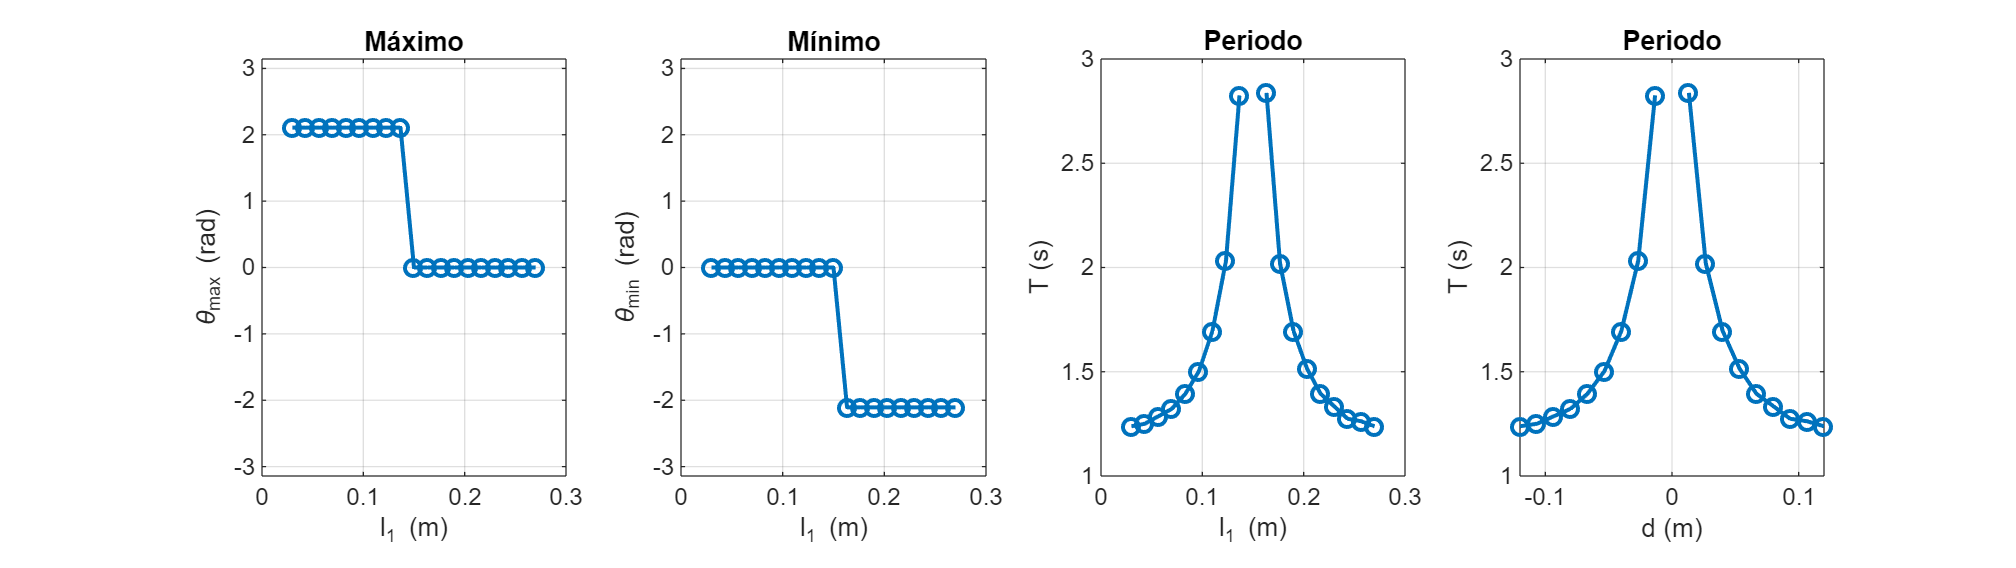

if show_thrust
    yyaxis(ax2, 'right')
    ylabel(ax2, 'Empuje (N)', 'Interpreter', 'tex', 'FontSize', 13);

    thrust1_line = animatedline(ax2, 'LineStyle', '--', 'LineWidth', 1.5);
    thrust2_line = animatedline(ax2, 'LineStyle', '-.', 'LineWidth', 1.5);

    % límites iniciales razonables; se pueden ajustar si quieres
    ylim(ax2, [0 1]);
    
    yyaxis(ax2, 'left')
end

legend_entries = {'\theta'};
if show_thrust
    legend_entries = {'\theta', 'T_1', 'T_2'};
end

%% Manually set subplot positions to prevent ylabel clipping
set(ax1, 'Position', [0.08 0.12 0.37 0.76]);
set(ax2, 'Position', [0.58 0.12 0.37 0.76]);

%% -------- Animation loop --------
T1_hist = zeros(size(t));
T2_hist = zeros(size(t));

for k = 1:length(t)
    th    = theta(k);
    thdot = theta_dot(k);

    x1  =  l1 * cos(th);   y1  =  l1 * sin(th);
    x2  = -l2 * cos(th);   y2  = -l2 * sin(th);
    xcg =   d * cos(th);   ycg =   d * sin(th);

    set(bar, 'XData', [x2 x1], 'YData', [y2 y1]);
    set(r1, 'XData', x1, 'YData', y1);
    set(r2, 'XData', x2, 'YData', y2);
    set(cg, 'XData', xcg, 'YData', ycg);


    delete(findall(ax1, 'Type', 'quiver'));

    [T1, T2] = thrust_fun(t(k), th, thdot);
    T1_hist(k) = T1;
    T2_hist(k) = T2;

    set(label_T1, 'String', sprintf('$T_1 = %.2f\\ \\mathrm{N}$', T1));
    set(label_T2, 'String', sprintf('$T_2 = %.2f\\ \\mathrm{N}$', T2));

    perp  = th + pi/2;
    scale = 0.05;

    quiver(ax1, x1, y1, scale*T1*cos(perp), scale*T1*sin(perp), 0, ...
        'r', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);

    quiver(ax1, x2, y2, scale*T2*cos(perp), scale*T2*sin(perp), 0, ...
        'Color', [0.1 0.6 0.1], 'LineWidth', 1.5, 'MaxHeadSize', 0.5);

    % theta
    yyaxis(ax2, 'left')
    addpoints(angle_line, t(k), th);
 
    % thrust
    if show_thrust
        yyaxis(ax2, 'right')
        addpoints(thrust1_line, t(k), T1);
        addpoints(thrust2_line, t(k), T2);

        max_thrust = max([1; T1_hist(1:k); T2_hist(1:k)]);
        ylim(ax2, [0 1.1*max_thrust]);
    end

    legend(ax2, legend_entries, 'Interpreter', 'tex', 'Location', 'best');

    drawnow limitrate
    pause(0.02);
end
end

#### 3.1.1 Simulación ejemplar

En esta sección se simula un ejemplo del comportamiento del aeropéndulo. Animamos al lector a que modifique los parámetros por sí mismo para familiarizarse con el modelo. Tomaremos los parámetros por defecto previamente seleccionados para una simulación inicial. Simularemos durante 10 segundos, discretizado en 500 puntos. 

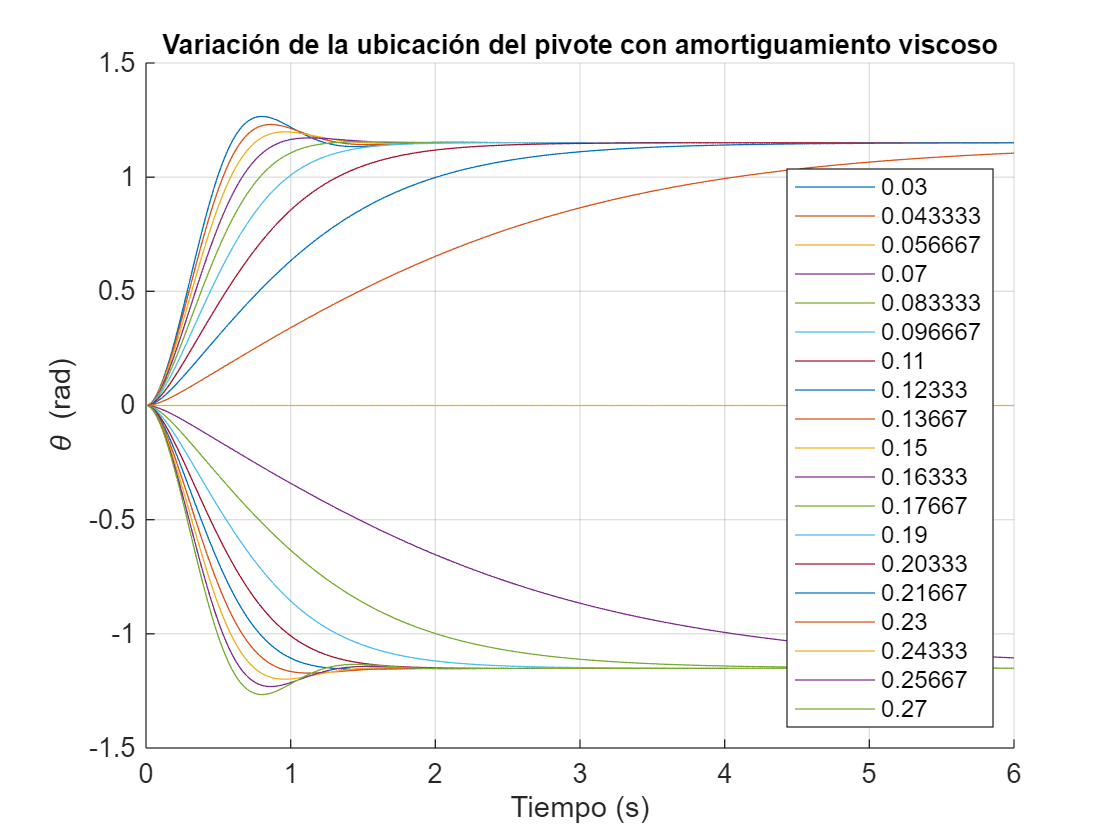

tspan = linspace(0,10,500);


% Simulación
[t,theta,theta_dot] = simulate_aeropendulum(params,x0,tspan,@thrust_constant);

% Gráfica
plot_aeropendulum_states(t,theta,theta_dot)

    l_1 (m)       d (m)       Ángulo máximo (rad)    Ángulo mínimo (rad)    Ángulo de Estabilización (rad)
    ________    __________    ___________________    ___________________    ______________________________

        0.03         -0.12             1.266                       0                      1.1508          
    0.043333      -0.10667            1.2308                       0                      1.1508          
    0.056667     -0.093333            1.1985                       0                      1.1508          
        0.07         -0.08            1.1719                       0                      1.1508          
    0.083333     -0.066667             1.155                       0                      1.1508          
    0.096667     -0.053333            1.1508                       0            

**Figura 2: Posición y velocidad angular de la simulación**

% Animación
animate_aeropendulum(t,theta,theta_dot,params,@thrust_constant, true)

**Figura 3: Simulación temporal del balancín eólico y su evolución angular**

### 3.2 Verificación del Modelo

Se procede a verificar el modelo: se probarán distintos escenarios y se compararán con el resultado esperado en la realidad. 

#### **3.2.1 Caso 1: Caso límite de un péndulo simple Ideal**

Se realiza una simulación sin fuerzas de empuje ni rozamiento con un solo brazo de palanca. Se espera que el sistema se comporte como un péndulo simple que no cese de oscilar de manera  sinusoidal.  Se toman los siguientes parámetros y entradas.

%% Parámetros físicos
params1.mb = 0;        % Masa (kg)
params1.m1 = 0.5;        % Masa (kg)
params1.m2 = 0;        % Masa (kg)
params1.l1 = 0.5;       % Distancia al rotor 1 (m)
params1.l2 = 0;       % Distancia al rotor 2 (m)
params1.g = 9.81;       % Gravedad (m/s^2)
params1.c = 0;        % Coeficiente de amortiguamiento (N·m·s/rad)

% Compute d, J, L, m
params1.L = params1.l1 + params1.l2;
params1.m = params1.mb + params1.m1 + params1.m2;
params1.d = params1.l1;
params1.J = params1.m*params1.d^2;

%% Condiciones iniciales para oscilaciones pequeñas
theta01 = 0;            % Posición en rad
theta_dot01 = 0;        % Velocidad angular en rad/s
x01 = [theta01; theta_dot01];


%% ---- Control de empuje nulo ----
function [T1,T2] = thrust_zero(~, ~, ~)
    T1 = 0;
    T2 = 0;
end

Habiendo definido los parámetros se realiza la simulación.

tspan1 = linspace(0,6,500);

% Simulación
[t1,theta1,theta_dot1] = simulate_aeropendulum(params1,x01,tspan1,@thrust_zero);
% Animación
animate_aeropendulum(t1,theta1,theta_dot1,params1,@thrust_zero, true)

**Figura 4: Simulación temporal del caso límite del péndulo ideal y su evolución angular**

Se evaluará ahora este comportamiento para distintos valores de $L = l_1$ y se verificará que el periodo de oscilación de la simulación es $T = 2\pi\sqrt{\frac{L}{g}$ como lo predice el modelo de péndulo simple para ángulos $\phi$pequeños. Se probará con $\phi = 10\degree $.

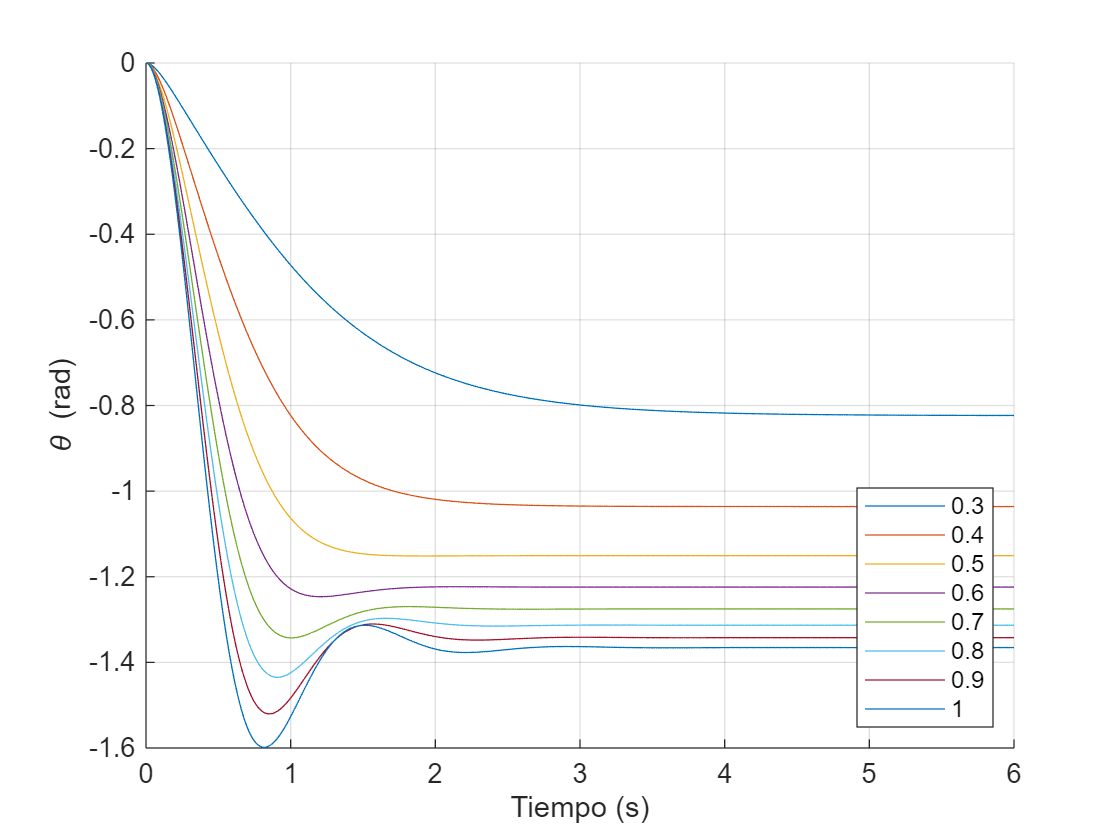

%% Definimos valores de l1 para la simulación de parámetros.
l1_values = linspace(0.2,1,9)';

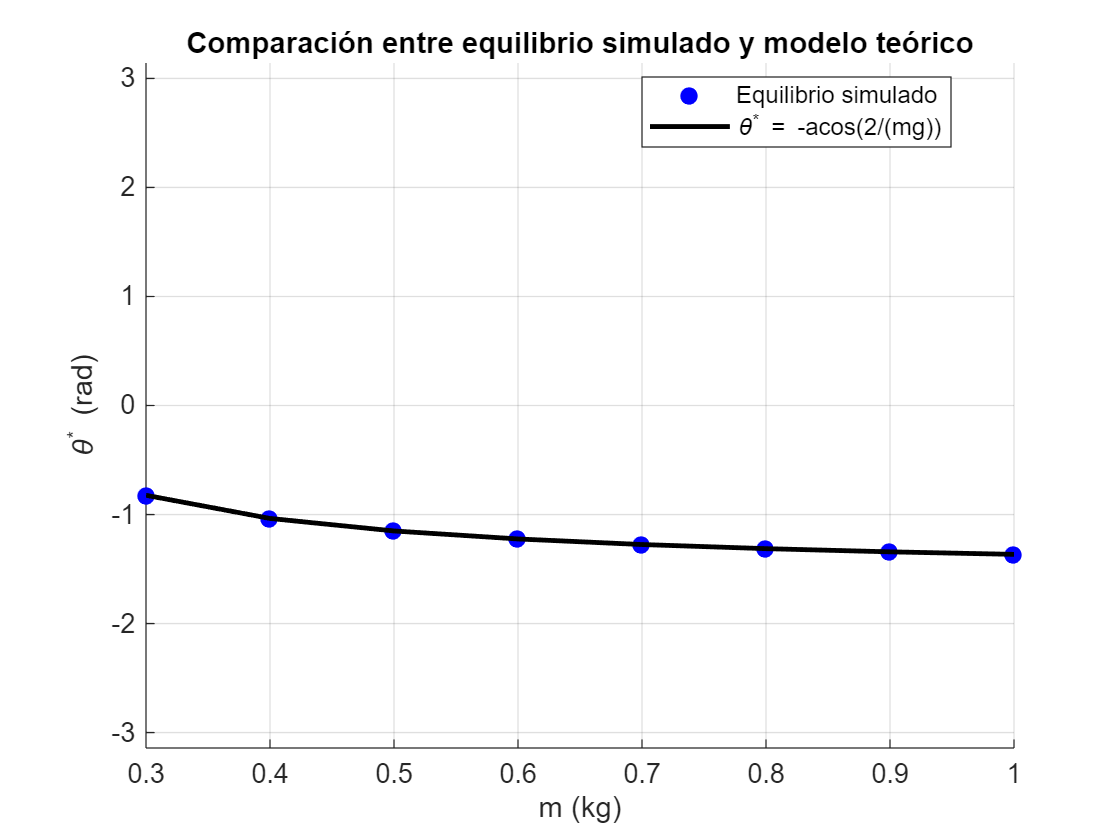


% Arreglos en los que se guardará el periodo teórico y experimental.
T_sim    = zeros(9,1);   % 9x1 column
T_theory = zeros(9,1);   % 9x1 column

figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')

%% Condiciones iniciales para oscilaciones pequeñas
theta01 = -1.39626;            % Posición en rad
theta_dot01 = 0;        % Velocidad angular en rad/s
x01 = [theta01; theta_dot01];

for i = 1:9
    params1.l1 = l1_values(i);
    % Recomputar parámetros m, J, L, d
    params1.L = params1.l1 + params1.l2;
    params1.m = params1.mb + params1.m1 + params1.m2;

    params1.d = params1.l1;
    params1.J = params1.m*params1.d^2;

    % Simular sistema
    [t1,theta1,theta_dot1] = simulate_aeropendulum(params1,x01,tspan1,@thrust_zero);
    plot(t1,theta1)

    %% Estimar periodo en base a los picos
    [~,locs] = findpeaks(theta1,t1);

    if length(locs) >= 2
        T_sim(i) = locs(2) - locs(1);
    else
        T_sim(i) = NaN;
    end

    %% Periodo Teórico
    T_theory(i) = 2*pi*sqrt(params1.l1/params1.g);

end
legend(string(l1_values),'Location','southeast')

**   Figura 5: Dinámica del péndulo simple ideal con la variación de **$l_1$

per_error = abs(T_sim - T_theory)./T_theory * 100;

T_table = table(l1_values, T_sim, T_theory, per_error, ...
    'VariableNames', {'l_1 (m)','Periodo simulado (s)','Periodo teórico (s)','Erro rrelativo (%)'});
disp(T_table)

**Tabla 4: Dependencia del periodo simulado con respecto a **$l_1$** y comparación con el periodo teórico**

#### **3.2.2 Caso 2: Variación de la ubicación del pivote sin fricción viscosa**

Se analiza el efecto de variar la posición del pivote a lo largo de una barra de longitud $L = 30 \text{ cm}$.  Con condiciones iniciales iguales a cero, se analizará el caso primero sin fricción viscosa.

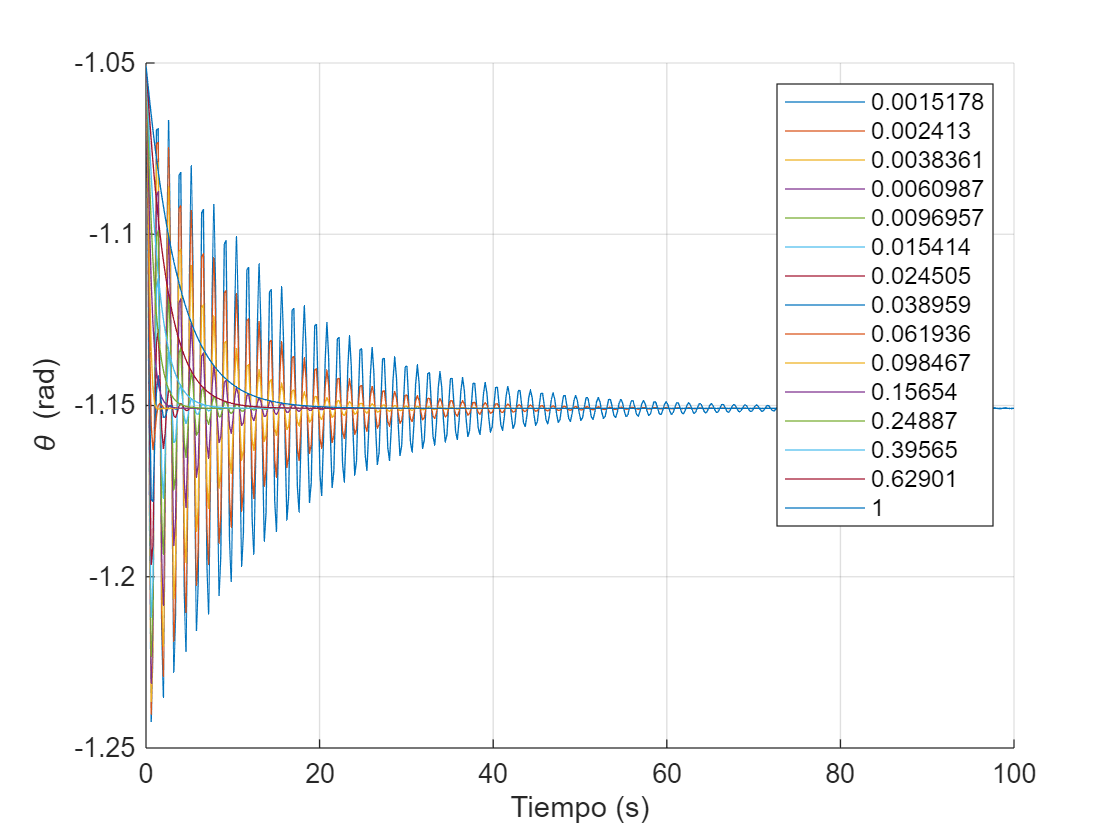

%% Intervalo de tiempo de simulación
tspan2 = linspace(0,6,500);
n = 19; % Número de datos

%% Parámetros físicos del sistema
params2.mb = 0.1;      % Masa del cuerpo central (kg)
params2.m1 = 0.2;      % Masa del rotor 1 (kg)
params2.m2 = 0.2;      % Masa del rotor 2 (kg)
params2.g  = 9.81;     % Aceleración de la gravedad (m/s^2)
params2.c  = 0;        % Coeficiente de amortiguamiento (N·m·s/rad)

%% Condiciones iniciales
theta02 = 0.0;         % Ángulo inicial (rad)
theta_dot02 = 0;       % Velocidad angular inicial (rad/s)
x02 = [theta02; theta_dot02];

%% Valores de l1 que se desean analizar
l1_values = linspace(0.03,0.27,n)';

%% Inicialización de arreglos para almacenar resultados
theta_max = zeros(n,1);   % Valor máximo del ángulo
theta_min = zeros(n,1);   % Valor mínimo del ángulo
d  = zeros(n,1);          % Distancia del pivote al centro de gravedad.
T_sim     = zeros(n,1);   % Periodo estimado de oscilación

%% Figura para visualizar las trayectorias temporales
figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')

for i = 1:n
    
    %% Actualizar parámetros geométricos
    params2.l1 = l1_values(i);       % Distancia al rotor 1
    params2.l2 = 0.30 - params2.l1;  % Distancia al rotor 2
    
    % Recalcular parámetros derivados del modelo
    params2 = aeropendulum_compute_params(params2);

    %% Simulación del sistema dinámico
    [t2,theta2,theta_dot2] = simulate_aeropendulum(params2,x02,tspan2,@thrust_constant);

    %% Graficar respuesta temporal
    plot(t2,theta2)

    %% Guardar características de la señal
    theta_max(i) = max(theta2);      % Valor máximo
    theta_min(i) = min(theta2);      % Valor mínimo
    d(i)  = params2.d;      % Valor final (equilibrio)

    %% Estimación del periodo usando picos de la señal
    [~,locs] = findpeaks(theta2,t2);


    if length(locs) >= 2
        T_sim(i) = locs(2) - locs(1);   % Diferencia entre dos picos consecutivos
    else
        T_sim(i) = NaN;                 % Si no hay suficientes picos
    end

end

%% Mostrar leyenda con los valores de l1
legend(string(l1_values),'Location','southeast')

**Figura 6: Dinámica del balancín eólico con respecto a la variación de **$l_1$** sin amortiguamiento viscoso**

%% Crear tabla de resultados
results_table = table(l1_values, d, theta_max, theta_min, T_sim, ...
    'VariableNames', {'l_1 (m)', 'd (m)', 'Ángulo máximo (rad)','Ángulo mínimo (rad)','Periodo (s)'});

disp(results_table)

**Tabla 5: Dependencia del periodo simulado, ángulos máximos y mínimos alcanzados con respecto a **$l_1$** sin amortiguamiento viscoso**

%% Figura resumen de características dinámicas

Coeficiente de amortiguamiento crítico aproximado: 0.044772


figure('Units','normalized','Position',[0 0 0.7 0.35])

Tiempo mínimo de estabilización: 0.4008 s


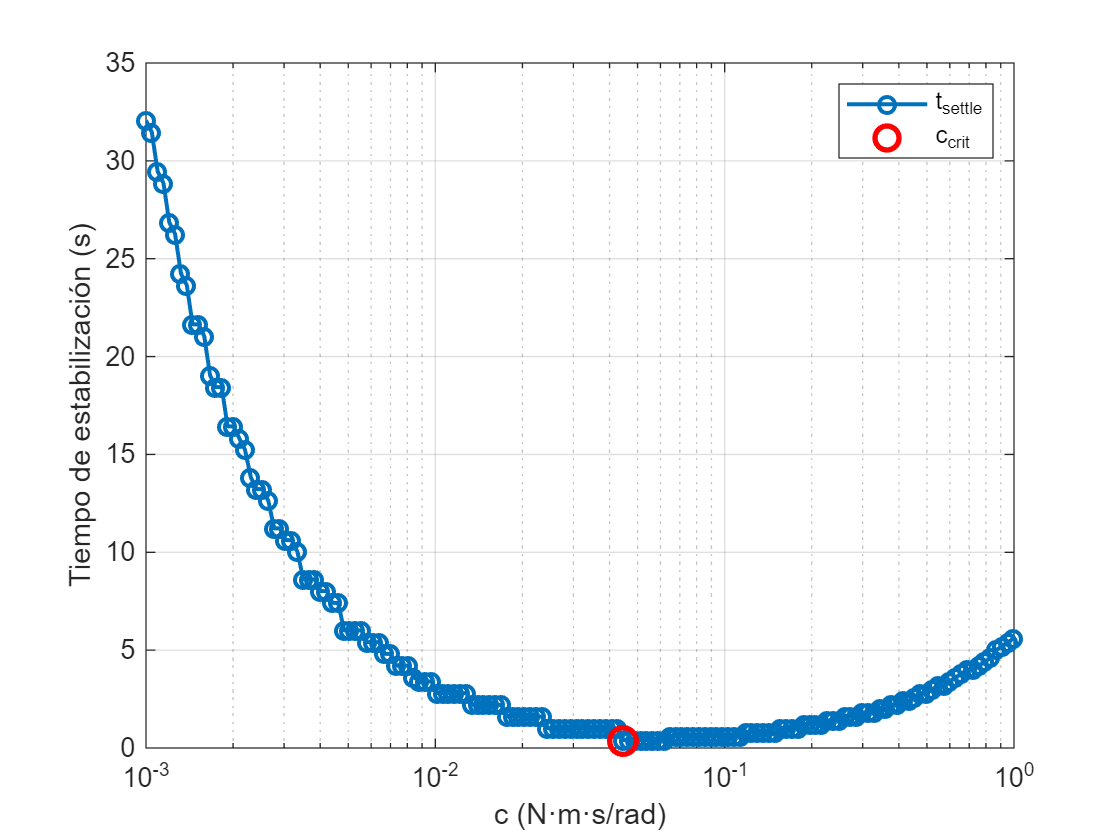


tiledlayout(1,4)

%% Ángulo máximo
nexttile
plot(l1_values,theta_max,'o-','LineWidth',1.5)
xlabel('l_1 (m)')

ylabel('\theta_{max} (rad)')
title('Máximo', 'FontSize',10,'FontWeight','bold')
ylim([-pi pi])
grid on

%% Ángulo mínimo
nexttile
plot(l1_values,theta_min,'o-','LineWidth',1.5)
xlabel('l_1 (m)')
ylabel('\theta_{min} (rad)')
title('Mínimo', 'FontSize',10,'FontWeight','bold')
ylim([-pi pi])
grid on

%% Periodo de oscilación
nexttile
plot(l1_values,T_sim,'o-','LineWidth',1.5)
xlabel('l_1 (m)')
ylabel('T (s)')
title('Periodo', 'FontSize',10,'FontWeight','bold')
grid on
%% Periodo de oscilación
nexttile
plot(d,T_sim,'o-','LineWidth',1.5)
xlabel('d (m)')
ylabel('T (s)')
title('Periodo', 'FontSize',10,'FontWeight','bold')
grid on

**Figura 7: Características dinámicas de la variación del pivote sin amortiguamiento viscoso**

#### **3.2.3 Caso 3: Variación de la ubicación del pivote con fricción viscosa**

Probaremos con un coeficiente de ficción viscosa distinto de cero, $c= 0.1\text{ N\cdotp m}$, con los mismos parámetros del Caso 2.

%% Intervalo de tiempo de simulación
tspan3 = linspace(0,6,500);
n = 19; % Número de simulaciones

%% Parámetros físicos del sistema
param3.mb = 0.1;      % Masa del cuerpo central (kg)
param3.m1 = 0.2;      % Masa del rotor 1 (kg)
param3.m2 = 0.2;      % Masa del rotor 2 (kg)
param3.g  = 9.81;     % Aceleración de la gravedad (m/s^2)
param3.c  = 0.1;      % Coeficiente de amortiguamiento viscoso (N·m·s/rad)

%% Condiciones iniciales
theta03 = 0.0;        % Ángulo inicial (rad)
theta_dot03 = 0;      % Velocidad angular inicial (rad/s)
x03 = [theta03; theta_dot03];

%% Valores de l1 que se desean analizar
l1_values = linspace(0.03,0.27,n)';

%% Inicialización de arreglos para almacenar resultados
theta_max = zeros(n,1);   % Ángulo máximo alcanzado
theta_min = zeros(n,1);   % Ángulo mínimo alcanzado
d         = zeros(n,1);   % Distancia pivote–centro de gravedad
theta_eq  = zeros(n,1);   % Ángulo de equilibrio

%% Figura para visualizar las trayectorias temporales
figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')
title('Variación de la ubicación del pivote con amortiguamiento viscoso', ...
      'FontSize',10,'FontWeight','bold')

for i = 1:n
    
    %% Actualizar parámetros geométricos
    param3.l1 = l1_values(i);          % Distancia al rotor 1
    param3.l2 = 0.30 - param3.l1;      % Distancia al rotor 2
    
    %% Recalcular parámetros derivados del modelo
    param3 = aeropendulum_compute_params(param3);

    %% Simulación del sistema dinámico
    [t3,theta3,theta_dot3] = simulate_aeropendulum(param3,x03,tspan3,@thrust_constant);

    %% Graficar respuesta temporal
    plot(t3,theta3)

    %% Guardar características de la señal
    theta_max(i) = max(theta3);     % Máximo
    theta_min(i) = min(theta3);     % Mínimo
    d(i)         = param3.d;        % Distancia pivote–centro de gravedad
    theta_eq(i)  = theta3(end);     % Ángulo de equilibrio

end

%% Mostrar leyenda con los valores de l1
legend(string(l1_values),'Location','southeast')

**Figura 8: Dinámica del balancín eólico con respecto a la variación de **$l_1$** con amortiguamiento viscoso**

%% Tabla de resultados
results_table = table(l1_values, d, theta_max, theta_min, theta_eq, ...
    'VariableNames', {'l_1 (m)', 'd (m)', 'Ángulo máximo (rad)','Ángulo mínimo (rad)','Ángulo de Estabilización (rad)'});

disp(results_table)

**Tabla 6: Dependencia del periodo simulado, ángulos máximos y mínimos alcanzados con respecto a **$l_1$** con amortiguamiento viscoso**

#### **3.2.4 Energía del Sistema y Puntos de Equilibrio**

Se considera la energía mecánica total del sistema, definida como la suma de la energía cinética rotacional, la energía potencial gravitacional y la energía potencial asociada al torque impuesto. Esta energía está dada por


$$\matrix{V(\theta,\dot{\theta})=
\frac{1}{2}J\dot{\theta}^2 + mgd\sin(\theta) - \tau \theta, && (10)}
$$


donde $\tau = T_1l_1 - T_2l_2$ representa el torque constante generado por los empujes aerodinámicos. Derivando esta expresión respecto al tiempo se obtiene


$$\matrix{\dot V =
J\dot{\theta}\ddot{\theta} + mgd\cos(\theta)\dot{\theta} - \tau \dot{\theta}., && (11)}
$$


Utilizando la ecuación de movimiento del sistema y sustituyendo la aceleración angular en $\dot{V}$ se obtiene que la variación de la energía del sistema depende solo del término de fricción viscosa


$$
\matrix{\dot V =
\dot{\theta}(\tau - mgd\cos(\theta) - c\dot{\theta})
+
mgd\cos(\theta)\dot{\theta}
-
\tau\dot{\theta}
, && (12)}\\


\matrix{


\dot V =
\tau\dot{\theta}
-
mgd\cos(\theta)\dot{\theta}
-
c\dot{\theta}^2
+
mgd\cos(\theta)\dot{\theta}
-
\tau\dot{\theta}
, && (13)}\\



\matrix{\dot V = -c\dot{\theta}^2, && (14)}\\


$$


Por lo tanto, para un coeficiente de amortiguación positivo, $\dot V \le 0,$ con igualdad únicamente cuando $\dot{\theta}=0$. Esto implica que la energía mecánica del sistema es monótonamente decreciente debido a la fricción viscosa y hay disipación de la energía. Dado que la energía mecánica es decreciente y está acotada inferiormente, se tiene que


$$\matrix{\lim_{t\to\infty}\dot{\theta}(t)=0. && (15)}\\

$$


En este régimen estacionario también se cumple que $\dot{\theta} = 0\text{ rad/s}, \ddot{\theta}=0 \text{ rad/s}^2$. Sustituyendo estas condiciones de equilibrio en la dinámica del sistema se obtiene la condición de equilibrio


$$\matrix{\tau - mgd\cos(\theta^*) = 0. && (16)}\\

$$


Los puntos de equilibrio corresponden a


$$\matrix{\theta^* = \pm \arccos \left(\frac{T_1l_1 - T_2l_2}{mgd}\right). && (17)}$$


El modelo se estabiliza solo si


$$\matrix{\ \left|\frac{T_1l_1 - T_2l_2}{mgd}\right| \le1 && (18)}\\

$$


Los puntos de equilibrio se denotarán como $(\mathbf{x_e}, \mathbf{u_e})$. Para el Caso 2 estudiado, con empuje $T_1 = T_2 = 1 \text{ N}$ igual y constante y con la definición previemente fijada de $d
$, vemos que los puntos predichos por el modelo matemático son, 


$$\matrix{\theta^* = \pm \arccos \left(\frac{2}{mg}\right). && (19)}\\

$$


### 3.3 Variación de Parámetros

#### 3.2.5 Caso 4: Variación de la Masa

Con los mismos parámetros del Caso 3, con $l_1 = 0.21 \text{ m}, l_2 = 0.9 \text{ m}$ pero variando la masa entre $0.3 \text{ kg} - 1.0 \text{ kg}$, comprobamos que los puntos de equilibrio cumplen $\theta^* = - \arccos 2/mg.$

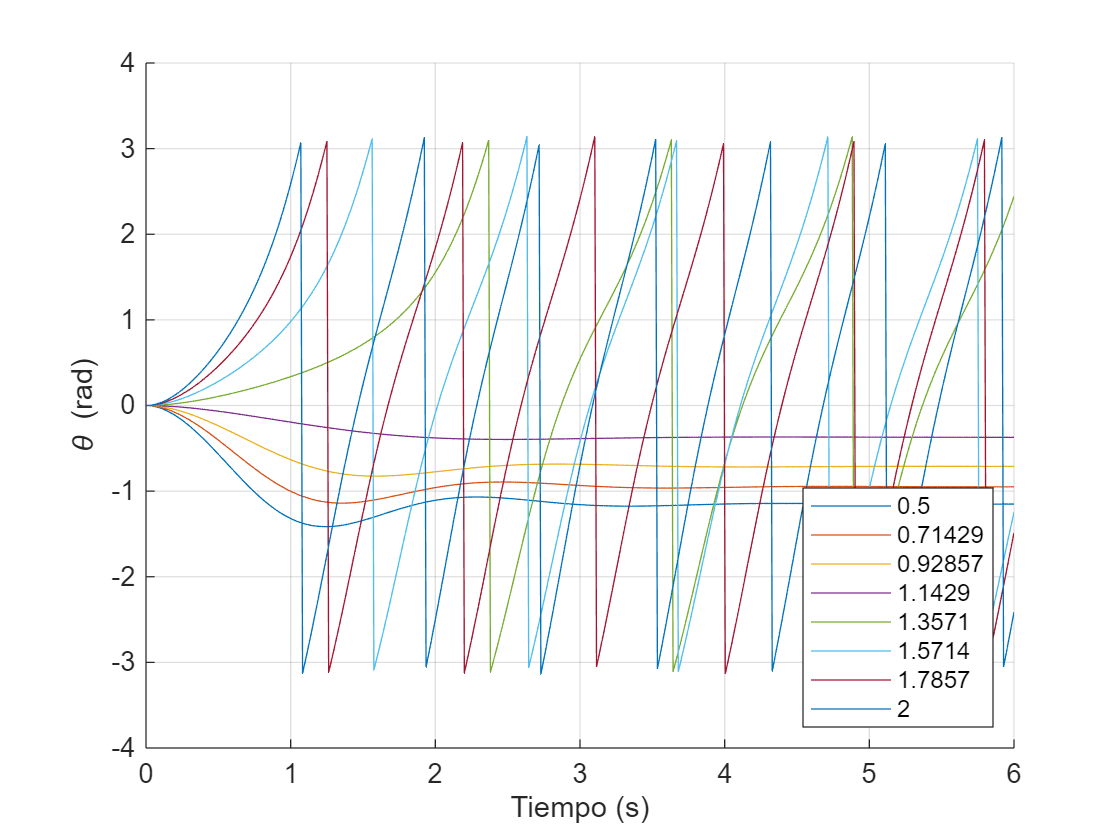

%% Intervalo de tiempo de simulación
tspan4 = linspace(0,6,500);

n = 8; % Número de simulaciones

%% Parámetros físicos del sistema
param4.g  = 9.81;     % Aceleración de la gravedad (m/s^2)
param4.c  = 0.1;      % Coeficiente de amortiguamiento viscoso (N·m·s/rad)
param4.l1 = 0.21;     % Distancia al rotor 1 (m)

    T1 (N)     T2 (N)    d (m)    Ángulo Máximo (rad)    Ángulo Mínimo (rad)    Desigualdad 18    ¿Cumple a Ecuación 18?
    _______    ______    _____    ___________________    ___________________    ______________    ______________________

        0.5      0        0.1                0                 -1.4148             0.40775                true          
    0.71429      0        0.1                0                 -1.1403              0.5825                true          
    0.92857      0        0.1                0                -0.82496             0.75724                true          
     1.1429      0        0.1                0                 -0.3959             0.93199                true          
     1.3571      0        0.1      

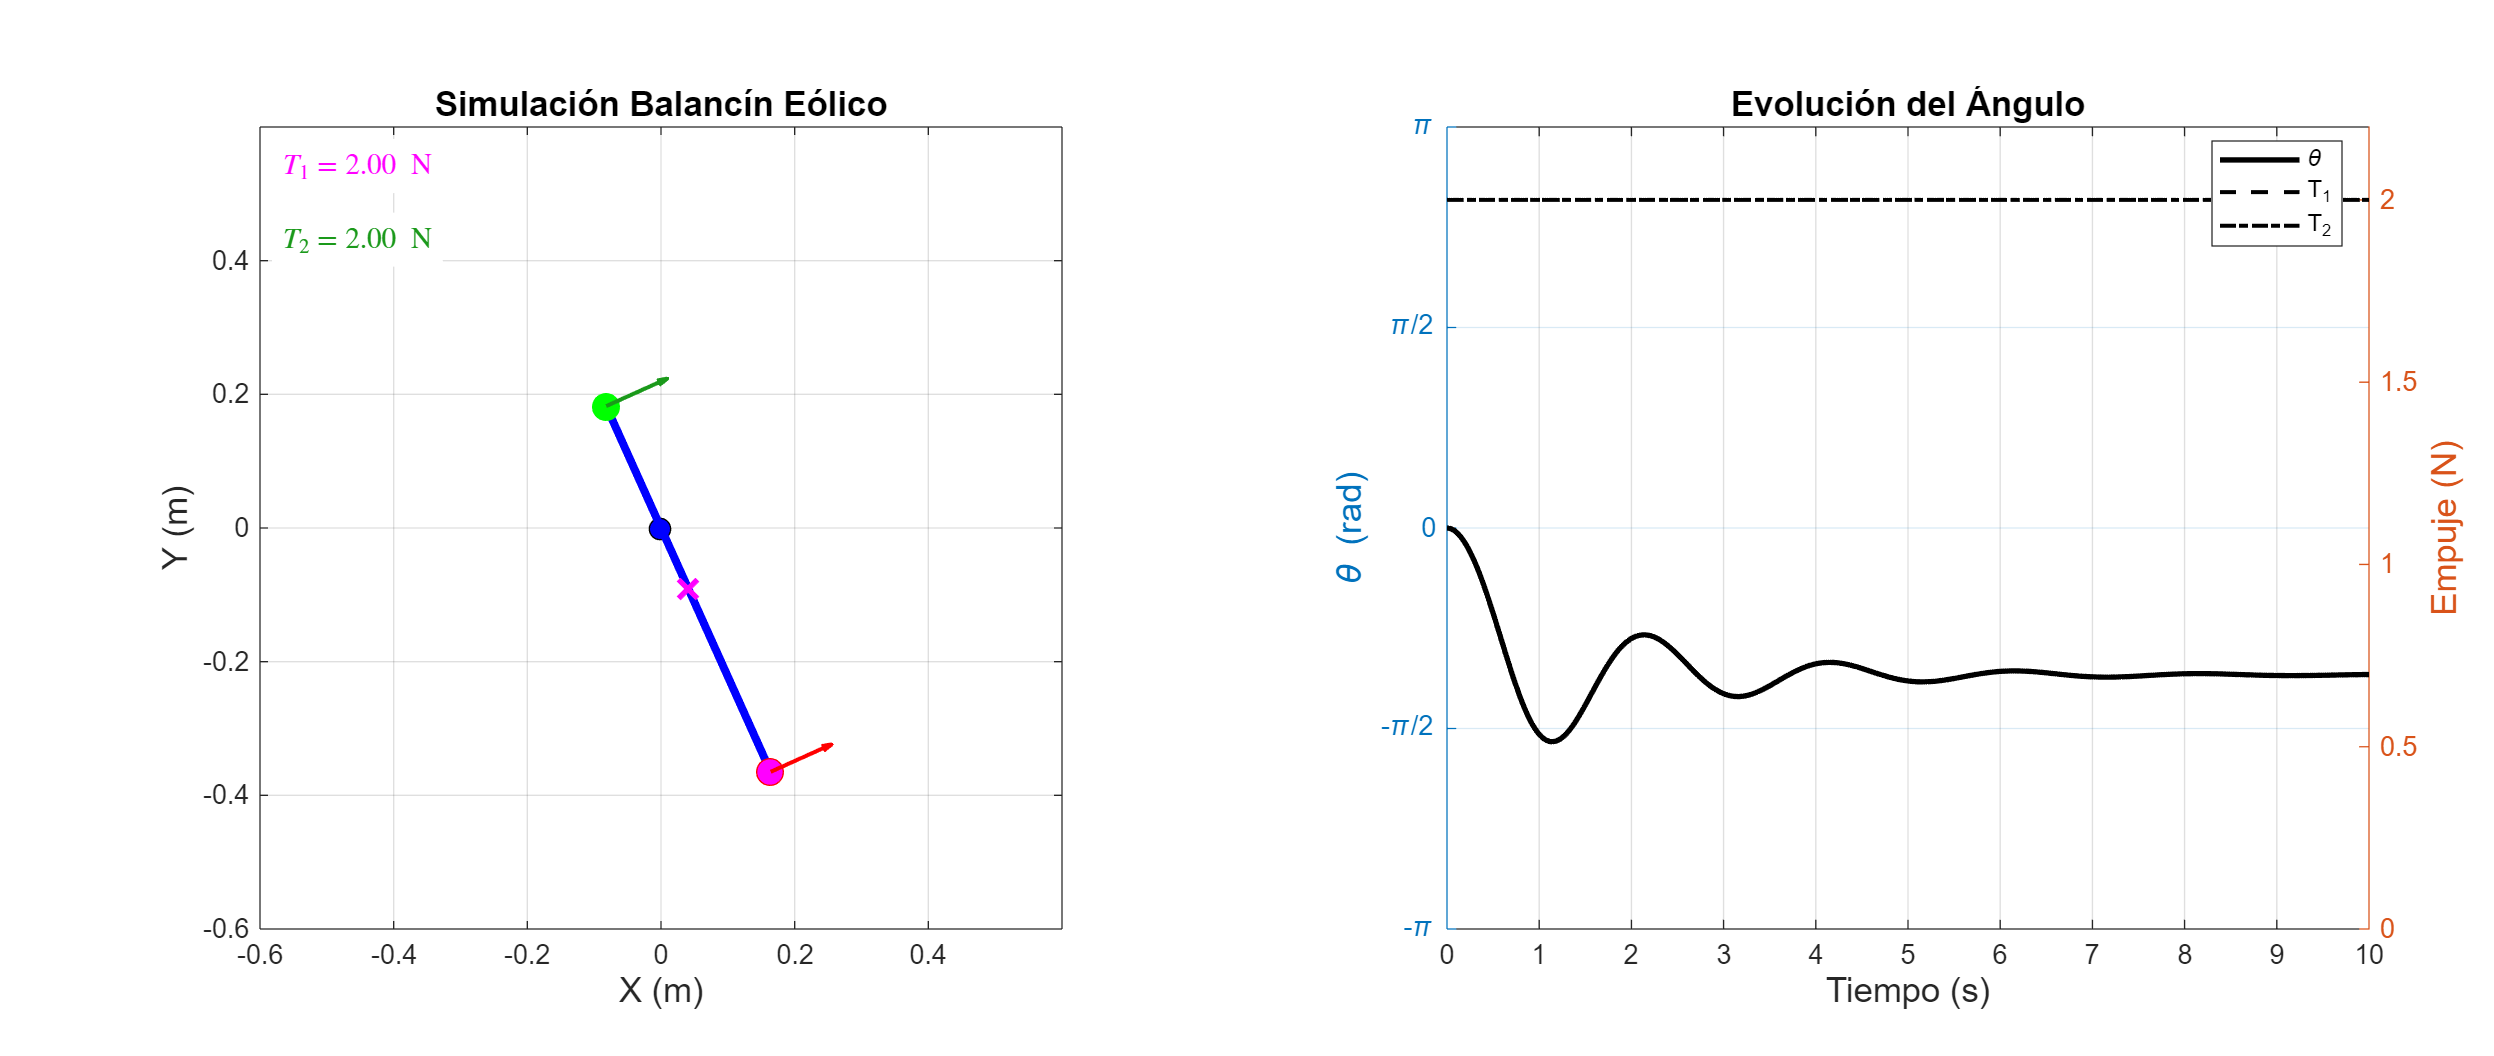

param4.l2 = 0.09;     % Distancia al rotor 2 (m)

%% Condiciones iniciales
theta04 = 0.0;        % Ángulo inicial (rad)
theta_dot04 = 0;      % Velocidad angular inicial (rad/s)
x04 = [theta04; theta_dot04];

%% Valores de masa total que se desean analizar
m_values = linspace(0.3,1,n)';

%% Inicialización de arreglos para almacenar resultados
d        = zeros(n,1);   % Distancia pivote–centro de gravedad
theta_eq = zeros(n,1);   % Ángulo de equilibrio

%% Figura para visualizar las trayectorias temporales
figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')
for i = 1:n
    
    %% Actualizar masa total
    param4.m = m_values(i);

    % Distribución de masas
    param4.mb = 0.2*param4.m;   % Masa del cuerpo central

    param4.m1 = 0.4*param4.m;   % Masa rotor 1
    param4.m2 = 0.4*param4.m;   % Masa rotor 2

    %% Recalcular parámetros derivados
    param4 = aeropendulum_compute_params(param4);

    %% Simulación del sistema dinámico
    [t4,theta4,theta_dot4] = simulate_aeropendulum(param4,x04,tspan4,@thrust_constant);

    %% Graficar respuesta temporal
    plot(t4,theta4)

    %% Guardar resultados
    d(i)        = param4.d;       % Distancia pivote–centro de gravedad
    theta_eq(i) = theta4(end);    % Ángulo de equilibrio alcanzado

end

%% Mostrar leyenda con los valores de masa
legend(string(m_values),'Location','southeast')

**Figura 9: Dinámica del balancín eólico con respecto a la variación de la masa con amortiguamiento viscoso**

%% Comparación con el modelo teórico del equilibrio

figure
hold on
grid on

% Equilibrios obtenidos por simulación
plot(m_values,theta_eq,'bo','MarkerFaceColor','b')

% Modelo teórico
theta_theory = -acos(2./(m_values*param4.g));
plot(m_values,theta_theory,'k','LineWidth',1.8)

xlabel('m (kg)')
ylabel('\theta^* (rad)')
title('Comparación entre equilibrio simulado y modelo teórico')

legend('Equilibrio simulado','\theta^* = -acos(2/(mg))','Location','best')

ylim([-pi pi])

**Figura 10: Comparación entre equilibrio simulado y modelo teórico con respecto a la variación de la masa con amortiguamiento viscoso**

Véase que el modelo teórico predice los resultados de la simulación, lo que indica que está bien implementado.

#### **3.2.6 Caso 5: Variación del coeficiente de fricción**

Con un alto coeficiente de fricción se espera que el sistema se estabilize más rápido. Para los parámetros por defecto, con  $l_1 = 0.21 \text{ m}, l_2 = 0.9 \text{ m}$. y valores del coeficiente de fricción variando logaritmicamente entre $c = 0.001\text{ N\cdot m\cdot s/rad} -  1 \text{ N\cdot m\cdot s/rad}$, se realiza el estudio de parámetros.

%% Intervalo de tiempo de simulación
tspan5 = linspace(0,100,500);
n = 150; % Número de simulaciones

%% Parámetros físicos del sistema
param5.g  = 9.81;     
param5.l1 = 0.21;     
param5.l2 = 0.09;     

%% Masa total fija
param5.m = 0.5;       

% Distribución de masas
param5.mb = 0.2*param5.m;   
param5.m1 = 0.4*param5.m;   
param5.m2 = 0.4*param5.m;   

%% Valores del coeficiente de fricción viscosa
c_values = logspace(-3,0,n)';   % mejor rango para detectar c_crit

%% Equilibrio teórico
theta_star = -acos(2/(param5.m*param5.g));

%% Condiciones iniciales
theta05 = theta_star + 0.1;        
theta_dot05 = 0;      
x05 = [theta05; theta_dot05];

%% Inicialización
theta_eq   = zeros(n,1);
t_settle   = NaN(n,1);

%% Figura de trayectorias
figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')

%% Tolerancia para tiempo de estabilización
tol = 0.02*abs(theta_star);

for i = 1:n
    
    %% Actualizar coeficiente de fricción
    param5.c = c_values(i);

    %% Recalcular parámetros derivados
    param5 = aeropendulum_compute_params(param5);

    %% Simulación
    [t5,theta5,theta_dot5] = simulate_aeropendulum(param5,x05,tspan5,@thrust_constant);

    %% Graficar algunas trayectorias
    if mod(i,10)==0
        plot(t5,theta5,'DisplayName',num2str(c_values(i)))
    end

    %% Guardar equilibrio numérico
    theta_eq(i) = theta5(end);

    %% Error respecto al equilibrio
    theta_error = theta5 - theta_star;
    abs_error = abs(theta_error);

    %% Tiempo de estabilización
    for k = 1:length(abs_error)

        if all(abs_error(k:end) < tol)
            t_settle(i) = t5(k);
            break
        end

    end

end

legend show

**Figura 11: Dinámica del balancín eólico con respecto a la variación del coeficiente de fricción viscosa**

%% -----------------------------
%% Tiempo de estabilización vs fricción

figure
semilogx(c_values,t_settle,'o-','LineWidth',1.5)
grid on

xlabel('c (N·m·s/rad)')
ylabel('Tiempo de estabilización (s)')

%% -----------------------------
%% Cálculo del amortiguamiento crítico

[ts_min,idx] = min(t_settle);

c_crit_sim = c_values(idx);

disp(['Coeficiente de amortiguamiento crítico aproximado: ', num2str(c_crit_sim)])
disp(['Tiempo mínimo de estabilización: ', num2str(ts_min),' s'])

%% -----------------------------
%% Marcar punto crítico en la gráfica

hold on
plot(c_crit_sim,ts_min,'ro','MarkerSize',10,'LineWidth',2)
legend('t_{settle}','c_{crit}')

**Figura 12: Tiempo de estabilización con respecto a la variación del coeficiente de fricción viscosa**

#### **3.2.6 Linealización del modelo en el punto de equilibrio y coeficiente de amortiguamiento crítico teórico.**

Como este es un sistema no-lineal, y el coeficiente de amortiguamiento crítico solo está definido para sistemas lineales de segundo orden, se linealiza el modelo en el punto de equilibrio, y se halla el coeficiente de amortiguameinto crítico, para hacer la verificación del Caso 5. Teniendo el modelo dinámico del balancín eólico $\dot{x} = f(\mathbf{x},\mathbf{u})$, obtenemos para los parámetros particulares según la sección 3.2.4 el punto de equilibrio estable $(\mathbf{x_e}, \mathbf{u_e})$ tal que $f(\mathbf{x_e},\mathbf{u_e})=0.$

Se definen pequeñas perturbaciones alrededor del punto de equilibrio equilibrio


$$\matrix{\mathbf{x(t)} = \mathbf{x_e} + \delta \mathbf{x(t)}, && (20)}\\

\matrix{\mathbf{\mathbf{u(t)} = \mathbf{u_e} + \delta\mathbf{u(t)}. && (21)}$$


La función $f(\mathbf{x},\mathbf{u})$ se expande alrededor del punto de equilibrio usando una serie de Taylor de primer orden:


$$\matrix{f(x,u) \approx f(x_e,u_e) + \left.\frac{\partial f}{\partial x}\right|_{x_e,u_e}\delta x + \left.\frac{\partial f}{\partial u}\right|_{x_e,u_e}\delta u
. && (22)}$$


Como$f(\mathbf{x_e},\mathbf{u_e})=0.$, el sistema linealizado queda $\delta\dot{x} = A\,\delta x + B\,\delta u$ donde 


$$\matrix{A =
\left.\frac{\partial f}{\partial x}\right|_{x_e,u_e},
\qquad
B =
\left.\frac{\partial f}{\partial u}\right|_{x_e,u_e}. && (23)}$$


Las derivadas parciales son


$$\matrix{A =
\left[
\begin{array}{cc}
0 & 1 \\
\frac{mgd}{J}\sin(x_1) & -\frac{c}{J}
\end{array}
\right], \qquad B =
\left[
\begin{array}{cc}
0 & 0 \\
\frac{l_1}{J} & - \frac{l_2}{J}
\end{array}
\right]. && (24)}$$


Por lo tanto, el sistema linealizado alrededor de $(\mathbf{x_e}, \mathbf{u_e})$ es


$$
\matrix{\delta\dot{x} =
\left[
\begin{array}{cc}
0 & 1 \\
\frac{mgd}{J}\sin(x_{1e}) & -\frac{c}{J}
\end{array}
\right]
\delta x
+
\left[
\begin{array}{cc}
0 & 0 \\
\frac{l_1}{J} & \frac{l_2}{J}
\end{array}\right]
\delta u. && (25)}$$


A partir del modelo linealizado del sistema y considerando como salida el ángulo del péndulo $y = \theta = x_1,$ se tiene $C =
\begin{array}{cc}
[1 & 0]
\end{array}, \quad
D = 0.$ La función de transferencia de un sistema lineal en espacio de estados está dada por $G(s) = C(sI-A)^{-1}B + D$ [5].


$$\matrix{sI-A =
\left[\begin{array}{cc}
s & -1 \\
-\frac{mgd}{J}\sin(\theta_e) & s + \frac{c}{J}
\end{array} \right].
&& (26)}$$


El determinante de esta matriz es 


$$\matrix{|sI-A| =s\left(s+\frac{c}{J}\right)
- \frac{mgd}{J}\sin(\theta_e),
&& (27)}\\
\matrix{|sI-A| = s^2 + \frac{c}{J}s - \frac{mgd}{J}\sin(\theta_e).
&& (28)}$$


Por lo tanto, la función de transferencia entre las entradas $U_1(s)$, $U_2(s)$ y la salida $\Theta (s)$es


$$\matrix{|sI-A| = G(s) = \frac{l_1}{Js^2 + cs - mgd\sin(\theta_e)} U_1(s) + \frac{-l_2}{Js^2 + cs - mgd\sin(\theta_e)}U_2(s).
&& (29)}$$


El denominador de la función de transferencia corresponde a un sistema de segundo orden. La forma estándar de un sistema de segundo orden es $s^2 + 2\zeta\omega_n s + \omega_n^2$, donde $\zeta$ es el coeficiente de amortiguamiento y $\omega_n$ la frecuencia natural. Comparando ambas expresiones se obtiene


$$\matrix{2\zeta\omega_n = \frac{c}{J} 
&& (30)}\\

\matrix{\omega_n^2 = \frac{mgd}{J}\sin(\theta_e).
&& (31)}
$$


De la segunda ecuación $\omega_n =
\sqrt{\frac{mgd}{J}\sin(\theta_e)}.$ El amortiguamiento crítico ocurre cuando $\zeta = 1$. Sustituyendo en la primera relación $\frac{c_{crit}}{J} = 2\omega_n,$ el coeficiente de amortiguamiento crítico del sistema es


$$\matrix{c_{crit}=2\sqrt{-Jmgd\sin(\theta_e)}.
&& (32)}$$


Para los parámetros del Caso 5, el amortiguamiento crítico rotacional,


$$\matrix{c_{crit}=2\sqrt{-(0.0115\ \mathrm{kg\cdotp m^2})(0.5\ \mathrm{kg})(9.81\ \mathrm{m/s^2})(0.06\ \mathrm{m})\sin(-1.15)} = 0.111 \mathrm{N\cdotp m \cdotp s}.
&& (33)}$$


### 3.4 Simulación con cambio de entradas para una entrada

#### **3.4.1 Caso 6: Simulación con empuje unilateral**

Retornamos a los parámetros originales, y cambiamos el empuje para que sea de un solo motor.

%% Intervalo de tiempo de simulación
tspan6 = linspace(0,6,500);
n = 8; % Número de simulaciones

%% Parámetros físicos del sistema
param6.g  = 9.81;     % Aceleración de la gravedad (m/s^2)
param6.c  = 0.1;      % Coeficiente de amortiguamiento viscoso (N·m·s/rad)
param6.l1 = 0.4;     % Distancia al rotor 1 (m)
param6.l2 = 0.2;     % Distancia al rotor 2 (m)

%% Masa total fija
param6.m = 0.5;       

% Distribución de masas
param6.mb = 0.2*param6.m;   
param6.m1 = 0.4*param6.m;   
param6.m2 = 0.4*param6.m;

%% Calcular parámetros derivados
param6 = aeropendulum_compute_params(param6);

%% Condiciones iniciales
theta06 = 0.0;        % Ángulo inicial (rad)
theta_dot06 = 0;      % Velocidad angular inicial (rad/s)
x06 = [theta06; theta_dot06];

%% Valores de empuje unilateral que se desean analizar
thrust_values = linspace(0.5,2,n)';

% Modelo de empuje constante para los rotores del aerobalancín.
function [T1,T2] = unilateral_thrust_params(~, ~, ~, thrust1)
% Salidas:
%   T1 -> Empuje generado por el rotor 1 (N)
%   T2 -> Empuje generado por el rotor 2 (N)

    T1 = thrust1;   % Empuje constante unilateral del rotor 1 (N)
    T2 = 0;   % Empuje nulo del rotor 2 (N)
end

%% Inicialización de arreglos para almacenar resultados
d        = zeros(n,1);   % Distancia pivote–centro de gravedad
theta_eq = zeros(n,1);   % Ángulo de equilibrio

%% Figura para visualizar las trayectorias temporales
figure
hold on
grid on
xlabel('Tiempo (s)')
ylabel('\theta (rad)')

%% Inicialización de arreglos para almacenar resultados
d               = zeros(n,1);   % Distancia pivote-centro de gravedad
theta_max       = zeros(n,1);   % Ángulo máximo
theta_min       = zeros(n,1);   % Ángulo mínimo
T1_values       = zeros(n,1);   % Empuje T1
T2_values       = zeros(n,1);   % Empuje T2
ratio_eq18      = zeros(n,1);   % |(T1*l1 - T2*l2)/(m*g*d)|
cumple_eq18     = false(n,1);   % ¿Se cumple la ecuación (17)?

for i = 1:n
    %% Actualizar empuje nuevo
    unilateral_thrust = @(t, theta, theta_dot) unilateral_thrust_params(t, theta, theta_dot, thrust_values(i));

    %% Simulación del sistema dinámico
    [t6,theta6,theta_dot6] = simulate_aeropendulum(param6,x06,tspan6, unilateral_thrust);

    %% Graficar respuesta temporal
    plot(t6,theta6)

    %% Obtener empujes usados
    [T1_i, T2_i] = unilateral_thrust(0,0,0);

    %% Guardar resultados básicos
    T1_values(i) = T1_i;
    T2_values(i) = T2_i;

    theta_max(i) = max(theta6);
    theta_min(i) = min(theta6);
    d(i)         = param6.d;

    %% Evaluar relación de la ecuación (17)
    denom = param6.m * param6.g * param6.d;

    if abs(denom) < 1e-12
        ratio_eq18(i) = NaN;
        cumple_eq18(i) = false;
    else
        ratio_eq18(i) = abs((T1_i*param6.l1 - T2_i*param6.l2)/denom);
        cumple_eq18(i) = ratio_eq18(i) <= 1;
    end

    %% Criterio simple para decidir si se estabiliza o sigue oscilando
    % Se mira el último 20% de la señal
    idx_tail = round(0.8*length(theta6)):length(theta6);
    theta_tail = theta6(idx_tail);
    theta_dot_tail = theta_dot6(idx_tail);

    amp_tail = max(theta_tail) - min(theta_tail);
    vel_tail = max(abs(theta_dot_tail));

    % Puedes ajustar estas tolerancias según tu simulación
    tol_amp = 1e-3;
    tol_vel = 1e-3;
end
%% Mostrar leyenda con los valores de empuje unilateral
legend(string(thrust_values),'Location','southeast')

**Figura 13: Dinámica con respecto a la variación del empuje unilateral**

%% Tabla de resultados
results_table = table( ...
    T1_values, T2_values, d, theta_max, theta_min, ratio_eq18, cumple_eq18, ...
    'VariableNames', {'T1 (N)','T2 (N)','d (m)','Ángulo Máximo (rad)','Ángulo Mínimo (rad)','Desigualdad 18','¿Cumple a Ecuación 18?'});
disp(results_table)

**Tabla 7: Resultados de la variación del empuje unilateral y verificación de la desigualdad 18. **

#### **3.4.2 Caso 7: Simulación con entrada constante**

%% Parámetros físicos
% Distribución de masas
params7.mb = 0.2;   
params7.m1 = 0.4;   
params7.m2 = 0.4;   
params7.l1 = 0.4;
params7.l2 = 0.2;
params7.d = 0.2;
params7.g = 9.81;
params7.c = 0.1;
params7 = aeropendulum_compute_params(params7);

tspan7 = linspace(0,10,500);

%% Condiciones iniciales
theta07 = 0;        
theta_dot07 = 0;      
x07 = [theta07; theta_dot07];
function [T1,T2] = thrust_step(~, ~, ~)
    T1 = 2;
    T2 = 2;
end

[t,theta,theta_dot] = simulate_aeropendulum(params7,x07,tspan7,@thrust_step);
animate_aeropendulum(t,theta,theta_dot,params,@thrust_step, true)

**Figura 14: Simulación temporal con entrada constante**

#### **3.4.3 Caso 8: Simulación con entrada sinusoidal**

function [T1,T2] = thrust_sin(t, ~, ~)
    T1 = 2*sin(2*pi*0.5*t) + 2;
    T2 = 2*sin(2*pi*0.5*t) + 2;
end

[t,theta,theta_dot] = simulate_aeropendulum(params7,x07,tspan7,@thrust_sin);
animate_aeropendulum(t,theta,theta_dot,params,@thrust_sin, true)

**Figura 15: Simulación temporal con entrada sinusoidal**

#### **3.4.4 Caso 9: Simulación con entrada delta**

function [T1,T2] = thrust_dirac(t,~,~)

t0 = 1;         % impulse time
dt = 0.1;       % pulse width

if abs(t - t0) < dt
    T1 = 10;
    T2 = 0;
else
    T1 = 0;
    T2 = 0;
end

end
[t,theta,theta_dot] = simulate_aeropendulum(params7,x07,tspan7,@thrust_dirac);
animate_aeropendulum(t,theta,theta_dot,params,@thrust_dirac, true)

**Figura 16: Simulación temporal con entrada delta**

### 4. Discusión

Para el Caso 1 del péndulo ideal simple, nótese que la respuesta a los parámetros de la Figura 4 es sinusoidal, por lo que representa un comportamiento límite en concordancia con el del péndulo simple. Cuando se varía $l_1$ en la Figura 5 se observa que todos estos comportamientos son armónicos, donde el periodo varía. Véase en la Tabla 4 que para un ángulo $\phi = 10\degree $ pequeño, el error relativo entre el periodo simulado y el periodo teórico es pequeño. Este error se debe a la linealización para ángulos pequeños $sin(\theta) \approx \theta$ usada para obtener la relación del periodo teórico. Esto confirma la Hipótesis 1. 

En cuanto al Caso 2, se observa un comportamiento oscilatorio del sistema entre la posición inicial y una posición determinada por los parámetros del modelo, confirmando la Hipótesis 2 (Véase Figura 6). En particular considerando la Tabla 6 y la Figura 7, se alcanza aproximadamente el mismo valor absoluto máximo y mínimo de la oscilación. Cuando $d$ se encuentra en el brazo $1$, el sistema oscila entre $0\text{ rad}$ y aproximadamente $-2.107 \text{ rad}$, mientras que cuando $d$ está en el brazo $2$, el sistema oscila entre $0\text{ rad}$ y aproximadamente $2.107\text{ rad}$. Cuando $d$ coincide con la posición del pivote, el sistema no oscila, ya que se encuentra directamente en un punto de equilibrio. Nótese que lo que sí varía entre estos casos es el periodo de oscilación, el cual depende únicamente de $|d|$, es decir, de la distancia entre el pivote y el centro de gravedad. En particular, a mayor distancia entre el pivote y el centro de gravedad, menor es el periodo de oscilación del sistema. Esto confirma la Hipótesis 3 Cuando el centro de gravedad está exactamente en el pivote, no hay dinámica.

Para el Caso 3, véase en la Figura 8 que todos estos sistemas un punto de equilibrio igual en su valor absoluto, excepto cuando el centro de gravedad está en el pivote donde no hay dinámica. Confirme que estos puntos de equilibrio son aproximadamente iguales en la Tabla 6, confirmando la Hipótesis 6 para estos parámetros específicos. Al encontrar la energía del sistema, su cambio y los puntos de equilibrio, vemos que este comportamiento se replica para cualquier conjunto de parámetros cuando $c \neq 0$. Al encontrar como varía la energía del sistema, vemos que para un $c > 0$, la energía se disipa en función de $\dot V = -c\dot{\theta}^2$. Esto explica por que en el Caso 2, el aeropéndulo tenía un comportamiento oscilatorio sin pérdida de energía, pero en el Caso 3, se disipa la energía hasta que el sistema llega a un equilibrio estable. Hallando los puntos de equilibrio, véase en la Ecuación 17 que el sistema tiene dos puntos de equilibrio, uno estable y otro inestable. Los equilibrios estables corresponden a mínimos locales de la energía potencial efectiva, mientras que los máximos corresponden a equilibrios inestables. Debido a la disipación de energía introducida por la fricción viscosa, las trayectorias del sistema convergen hacia el mínimo de energía potencial, lo cual explica la convergencia observada en las simulaciones. Véase en la Ecuación 18 que el punto de equilibrio no depende de $l_1$, como se ha comprobado en la simulación del Caso 3. Para los parámetros seleccionados $\theta^* \approx \pm 1.15 \text{ rad} $, que es exactamente lo que observamos en la simulación del Caso 3, negativo si $d
$ está en el brazo $l_1$, positivo si $d
$ está en el brazo $l_2$.

Con estos tres casos validamos que el modelo actúa como el sistema físico de un balancín eólico, reduciendo el sistema al caso límite de un péndulo ideal y comprobando que la energía del sistema se conserva en ausencia de amortiguamiento, produciendo oscilaciones persistentes, mientras que en presencia de fricción viscosa esta se disipa progresivamente hasta que el sistema converge hacia un punto de equilibrio estable.

Para el Caso 4 (véase la Figura 9), se valida la correcta implementación del modelo al variar la masa del sistema en presencia de amortiguamiento viscoso y comprobar que el comportamiento obtenido coincide con el predicho por el modelo matemático. En particular, se verifica la Hipótesis 5, según la cual, para una entrada constante, al aumentar la masa también aumenta el valor absoluto del punto de equilibrio (véase la Figura 10). No obstante, este incremento en el valor absoluto del punto de equilibrio es leve. 

En cuanto al Caso 5, la Hipótesis 6 se rechaza. El resultado puede parecer contraintuitivo en un primer momento, pero conduce a una observación importante sobre la dinámica del sistema. El sistema puede clasificarse en tres regímenes de amortiguamiento: subamortiguado, críticamente amortiguado y sobreamortiguado. En el régimen subamortiguado, aumentar el coeficiente de fricción viscosa reduce las oscilaciones del sistema, lo que provoca que el tiempo necesario para alcanzar el equilibrio disminuya. Es decir, un mayor amortiguamiento ayuda a disipar más rápidamente la energía del sistema y, por tanto, acelera su estabilización. Cuando el coeficiente de amortiguamiento alcanza el valor de amortiguamiento crítico, el sistema llega al equilibrio en el menor tiempo posible sin presentar oscilaciones. Este punto corresponde al tiempo de estabilización mínimo, que en este caso se aproxima a $c_{crit} \approx 0.1 \text{ N\cdotp m}$. Sin embargo, si el coeficiente de amortiguamiento continúa aumentando, el sistema pasa al régimen sobreamortiguado. En este caso, el movimiento del sistema se vuelve más lento porque la fricción es tan grande que limita la velocidad con la que el sistema puede desplazarse hacia el equilibrio. Como consecuencia, aunque ya no existen oscilaciones, el tiempo de estabilización vuelve a aumentar. Por lo tanto, existe un valor óptimo del coeficiente de amortiguamiento —el amortiguamiento crítico— que minimiza el tiempo necesario para que el sistema alcance el equilibrio correspondiente. 

Se linealizó el modelo con el objetivo de estimar el coeficiente de amortiguamiento crítico teórico. No obstante, como se observa en la Ecuación 32, el valor obtenido mediante la aproximación lineal no coincide con el amortiguamiento crítico identificado en el Caso 5. Esta diferencia puede atribuirse a la fuerte no linealidad del sistema, lo que sugiere que el modelo linealizado solo es válido en un rango reducido de operación y debe emplearse con cautela para analizar la dinámica del sistema.

Para el Caso 6, se comprueba la Hipótesis 7 únicamente para aquellos conjuntos de parámetros para los cuales no existe un punto de equilibrio, es decir, aquellos que no cumplen la condición expresada en la Ecuación 18 (Véase la Figura 13 y Tabla 7). Obsérvese que los sistemas que se estabilizan satisfacen la desigualdad 18, mientras que en aquellos casos en los que esta no se cumple, el empuje es capaz de superar el efecto del peso. Como consecuencia, el péndulo comienza a rotar continuamente debido a la acción del torque unilateral $T_1$.

El Caso 7 se presenta como referencia para comparar los resultados obtenidos en los Casos 8 y 9, ya que su comportamiento ha sido analizado a lo largo de todo este estudio. El Caso 8 confirma la Hipótesis 8: aun con una entrada sinusoidal, el sistema oscila de forma sinusoidal, presentando un desfase respecto a la entrada pero conservando el mismo periodo (véase la figura 15). Por su parte, el Caso 9 confirma la Hipótesis 9. Con una entrada tipo delta, el sistema tarda más tiempo en estabilizarse; en particular, se requieren aproximadamente 10 segundos para alcanzar el equilibrio, mientras que con una entrada constante el sistema se estabiliza alrededor de los 6 segundos (véanse la Figuras 15 y 14).

### 5. Bibliografía

[1] R. Breganon, U. N. L. T. Alves, J. P. L. S. De Almeida, F. S. F. Ribeiro, M. Mendonça, R. H. C. Palácios, and M. A. F. Montezuma, “Model identification and H∞ control of an aeropendulum,” *Journal of Applied Research and Technology*, vol. 21, no. 4, pp. 526–534, 2023. doi: 10.22201/icat.24486736e.2023.21.4.1741.

[2] K. Charoensuk, T. Saneewong Na Ayuthaya, P. Poungsri, L. Kirasamutranon, V. Suthiphasilp, G. Prayutte, and K. Pawananont, “The modelling and control for design aero-pendulum via proportional–integral–derivative and integral-proportional derivative,” in *Proc. 13th International Electrical Engineering Congress (iEECON)*, 2025, pp. 1–6.

[3] J. A. Alvarado Cortes, A. D. Cortes Hernandez, O. A. Domínguez Ramírez, J. D. Ramírez Zamora, J. Ortega Ventura, and L. A. Martínez Rivera, “Diseño, construcción y validación experimental de un aeropéndulo de una hélice con un grado de libertad,” *Iberociencias*, vol. 4, no. 4, pp. 1063–1092, 2025, doi: 10.63371/ic.v4.n4.a424.

[4] H. Goldstein, C. Poole, and J. Safko, *Classical Mechanics*, 3rd ed. Boston, MA, USA: Addison-Wesley, 2002.

[5] C. M. Vélez S., *Sistemas dinámicos en contexto: Modelación matemática, simulación, estimación y control con MATLAB*, vol. 24. Editorial EAFIT, 2024.